% load('/Users/platel/Desktop/exp/brainbow hippocampus/best/23_12_24_16_42_06P2M_411582_230320_plane1_2023_04_05.17-57-09assemblysce6last/brainbow.mat')%,'Tr1b','WinActive','WinRest','Race')
% load ("E:\Data\Aurelie\analysis\august2025\assembly\nocues\allresults.mat");
% load ("E:\Data\Aurelie\analysis\august2025\assembly\nocues\allbrainbowALL.mat"); 
clear

% idx = find(contains(matfile, {'444119'}) & contains(matfile, {'220919'}) & contains(matfile, {'plane0'}));
% load (cell2mat(matfile(idx(1))),'Tr1b','WinActive','WinRest','NCell');%,'Tr1b','WinActive','WinRest','Race'

if ispc
    Pathsave='E:\Data\Aurelie\analysis\December2025\correlation\nocues\';%PC
    load("E:\Data\Aurelie\data\nocues\nocues.mat");%PC
    load ("E:\Data\Aurelie\data\nocues\444119\220919_plane0\Fall.mat",'ops','stat','iscell')
    % filename=string(matfile{22});
    % openingnwb
    load("E:\Data\Aurelie\data\nocues\444119\220919_plane0\results.mat",'F','speed','WinRest', 'WinActive')
    % PathSave='E:\Data\Aurelie\analysis\November2025\assembly\cuesPCA\';%PC
    % load("E:\Data\Aurelie\data\cues\cues.mat")
elseif ismac
    path=['/Users/platel/Library/CloudStorage/GoogleDrive-jcplatel@gmail.com/Mon Drive/' ...
        'brainbow/data/444119/220919_plane0/'];
    load ('/Users/platel/Library/CloudStorage/GoogleDrive-jcplatel@gmail.com/Mon Drive/brainbow/data/444119/220919_plane0/Fall.mat','ops','F','iscell','stat')
    load(['/Users/platel/Library/CloudStorage/GoogleDrive-jcplatel@gmail.com/Mon Drive/' ...
        'brainbow/data/444119/220919_plane0/results.mat'],'F','speed','WinRest', 'WinActive')

end

% F=F(iscell(:,1)==1,:);
%Tr1b=double(F);

%Load colorcell
% load (['/Users/platel/Library/CloudStorage/GoogleDrive-jcplatel@gmail.com/Mon Drive/brainbow' ...
%     '/data/444119/220919_plane0/colorcell_registration.mat'])

load ("E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcell_registration.mat")

% %load colorcellnew if exist
% fileExists = isfile([path 'colorcellnew.mat']);
% if fileExists
%     load ([path 'colorcellnew.mat'])
% end

% load ('/Users/platel/Library/CloudStorage/GoogleDrive-jcplatel@gmail.com/Mon Drive/brainbow/data/444119/220919_plane0/colorcell.mat')

## Load calcium mask from suite2p (from Fall.mat)

m=0;
NCell=sum(iscell(:,1)>0);

for n=1 : length(stat)
    if iscell(n,1)==1
        m=m+1;
        % outline_gcampx(m)={double(stat{1, n}.xext+1)};
        % outline_gcampy(m)={double(stat{1, n}.yext+1)};
        % neuropil(m)={stat{1, n}.neuropil_mask};
        Coomasqx(m)={double(stat{1, n}.xpix+1)};%+1  to adpat suite2p output   ONLY 1 ??????
        Coomasqy(m)={double(stat{1, n}.ypix+1)};
    end
end

gcamp_centroid=zeros(NCell,2);

for n=1:NCell
    gcamp_centroid(n,:)=[mean(cell2mat(Coomasqx(1,n))),mean(cell2mat(Coomasqy(1,n)))];
end

mask_to_keep = colorcell < 7;
gcamp_centroid=gcamp_centroid(mask_to_keep,:);

%options
options.MinPeakDistancesce = 5;
options.MinPeakDistance    = 3;
options.threshold_peak     = 3;
options.synchronous_frames = 2;
options.sce_n_cells_threshold = 10;
options.percentile         = NaN;
options.minithreshold      = 0.1;
options.SG_window          = 7;
options.PCA_test = false;

%pre-process data
corrXY = ops.corrXY;
F=double(F);
[DataOut, Stats, options] = preprocessing_5(F, speed, corrXY, colorcell, options);

nSCE après filtrage bad_frames : 419
Sum transient: 145632


Tr1b = DataOut.Tr1b;
DF =  Tr1b(:,WinRest);
colorcell=DataOut.colorcell;

## calcul correlation Pearson cellules meme couleur vs cellules couleurs différentes


%%En général, est-ce que deux cellules qui partagent une couleur 
% (peu importe laquelle) sont plus synchronisées que deux cellules 
% de couleurs différentes ?"

%% 1. Préparation des données et Calcul Réel (Observé)
N_perms = 10000; % Nombre de permutations 

% Calcul de la matrice de corrélation globale 
% corrcoef attend les variables en colonnes, donc on transpose DF'
All_Corr = corrcoef(DF'); 
N_cells = size(All_Corr, 1);

% Création d'un masque pour le triangle supérieur strict (k=1)
% IMPORTANT : On exclut la diagonale (k=0) car la corrélation d'une cellule 
% avec elle-même est toujours 1, ce qui fausserait la moyenne.
UpperTriMask = triu(true(N_cells), 1);

% Définition des groupes réels
% La matrice 'IsSameColor' vaut 1 si la paire (i,j) a la même couleur, 0 sinon.
[GridColors1, GridColors2] = meshgrid(colorcell, colorcell);
Real_SameMask = (GridColors1 == GridColors2) & UpperTriMask;
Real_DiffMask = (GridColors1 ~= GridColors2) & UpperTriMask;

% Calcul des moyennes observées
mean_same_obs = mean(All_Corr(Real_SameMask));
mean_diff_obs = mean(All_Corr(Real_DiffMask));
diff_obs = mean_same_obs - mean_diff_obs;

fprintf('Différence observée (Même - Différent) : %.5f\n', diff_obs);

Différence observée (Même - Différent) : 0.00054


%% 2. Boucle de Permutation (Shuffling)
diff_shuffled = zeros(N_perms, 1);
temp_colors = colorcell; % Copie temporaire pour mélanger

% On utilise une barre de progression car 10k itérations peuvent prendre quelques secondes
h = waitbar(0, 'Calcul des permutations...');

for k = 1:N_perms
    % Mélange aléatoire des positions des couleurs
    shuffled_colors = temp_colors(randperm(N_cells));
    
    % On recrée le masque "Même Couleur" avec les couleurs mélangées
    [S_Grid1, S_Grid2] = meshgrid(shuffled_colors, shuffled_colors);
    
    % Note : Pas besoin de recalculer corrcoef ! On réutilise All_Corr.
    % On change juste quels indices sont considérés "Même couleur".
    Perm_SameMask = (S_Grid1 == S_Grid2) & UpperTriMask;
    Perm_DiffMask = (S_Grid1 ~= S_Grid2) & UpperTriMask; % Le reste du triangle sup
    
    % Calcul de la différence fictive
    m_same = mean(All_Corr(Perm_SameMask));
    m_diff = mean(All_Corr(Perm_DiffMask));
    diff_shuffled(k) = m_same - m_diff;
    
    if mod(k, 1000) == 0
        waitbar(k/N_perms, h);
    end
end
close(h);

%% 3. Calcul de la P-value et Résultats
% P-value = Proportion de cas où le hasard a fait aussi bien ou mieux que la réalité
% (Test unilatéral : on teste si Same > Diff)
p_value = mean(diff_shuffled >= diff_obs);

fprintf('Différence réelle : %.5f\n', diff_obs);

Différence réelle : 0.00054


fprintf('P-value           : %.5f\n', p_value);

P-value           : 0.29070



if p_value < 0.05
    fprintf('CONCLUSION : Différence SIGNIFICATIVE.\n');
else
    fprintf('CONCLUSION : Pas de différence significative.\n');
end

CONCLUSION : Pas de différence significative.


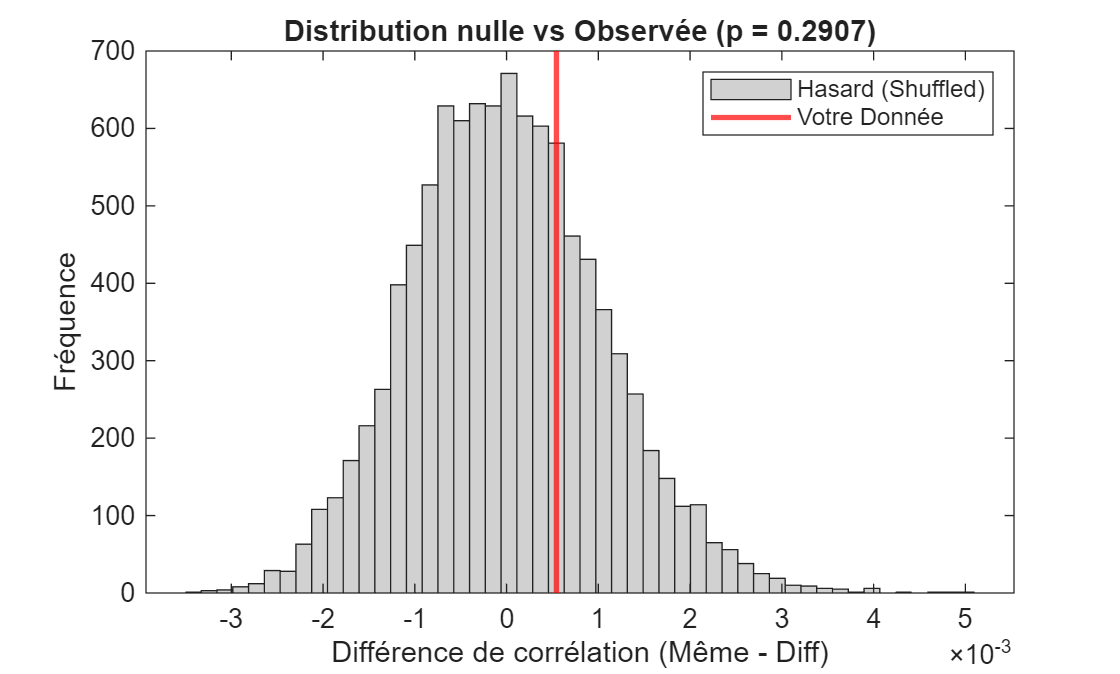


%% 4. Visualisation
figure;
histogram(diff_shuffled, 50, 'FaceColor', [.7 .7 .7]); hold on;
xline(diff_obs, 'r', 'LineWidth', 2);
xlabel('Différence de corrélation (Même - Diff)');
ylabel('Fréquence');
title(['Distribution nulle vs Observée (p = ' num2str(p_value) ')']);
legend('Hasard (Shuffled)', 'Votre Donnée');

## calcul correlation Spearman cellules meme couleur vs cellules couleurs différentes


%%En général, est-ce que deux cellules qui partagent une couleur 
% (peu importe laquelle) sont plus synchronisées que deux cellules 
% de couleurs différentes ?"

%% 1. Préparation des données et Calcul Réel (Observé)
N_perms = 10000; % Nombre de permutations 

% Calcul de la matrice de corrélation globale 
% corrcoef attend les variables en colonnes, donc on transpose DF'
% All_Corr = corrcoef(DF'); 
All_Corr = corr(DF','Type','Spearman'); 
N_cells = size(All_Corr, 1);

% Création d'un masque pour le triangle supérieur strict (k=1)
% IMPORTANT : On exclut la diagonale (k=0) car la corrélation d'une cellule 
% avec elle-même est toujours 1, ce qui fausserait la moyenne.
UpperTriMask = triu(true(N_cells), 1);

% Définition des groupes réels
% La matrice 'IsSameColor' vaut 1 si la paire (i,j) a la même couleur, 0 sinon.
[GridColors1, GridColors2] = meshgrid(colorcell, colorcell);
Real_SameMask = (GridColors1 == GridColors2) & UpperTriMask;
Real_DiffMask = (GridColors1 ~= GridColors2) & UpperTriMask;

% Calcul des moyennes observées
mean_same_obs = mean(All_Corr(Real_SameMask));
mean_diff_obs = mean(All_Corr(Real_DiffMask));
diff_obs = mean_same_obs - mean_diff_obs;

fprintf('Différence observée (Même - Différent) : %.5f\n', diff_obs);

Différence observée (Même - Différent) : 0.00045


%% 2. Boucle de Permutation (Shuffling)
diff_shuffled = zeros(N_perms, 1);
temp_colors = colorcell; % Copie temporaire pour mélanger

% On utilise une barre de progression car 10k itérations peuvent prendre quelques secondes
h = waitbar(0, 'Calcul des permutations...');

for k = 1:N_perms
    % Mélange aléatoire des positions des couleurs
    shuffled_colors = temp_colors(randperm(N_cells));
    
    % On recrée le masque "Même Couleur" avec les couleurs mélangées
    [S_Grid1, S_Grid2] = meshgrid(shuffled_colors, shuffled_colors);
    
    % Note : Pas besoin de recalculer corrcoef ! On réutilise All_Corr.
    % On change juste quels indices sont considérés "Même couleur".
    Perm_SameMask = (S_Grid1 == S_Grid2) & UpperTriMask;
    Perm_DiffMask = (S_Grid1 ~= S_Grid2) & UpperTriMask; % Le reste du triangle sup
    
    % Calcul de la différence fictive
    m_same = mean(All_Corr(Perm_SameMask));
    m_diff = mean(All_Corr(Perm_DiffMask));
    diff_shuffled(k) = m_same - m_diff;
    
    if mod(k, 1000) == 0
        waitbar(k/N_perms, h);
    end
end
close(h);

%% 3. Calcul de la P-value et Résultats
% P-value = Proportion de cas où le hasard a fait aussi bien ou mieux que la réalité
% (Test unilatéral : on teste si Same > Diff)
p_value = mean(diff_shuffled >= diff_obs);

fprintf('Différence réelle : %.5f\n', diff_obs);

Différence réelle : 0.00045


fprintf('P-value           : %.5f\n', p_value);

P-value           : 0.30910



if p_value < 0.05
    fprintf('CONCLUSION : Différence SIGNIFICATIVE.\n');
else
    fprintf('CONCLUSION : Pas de différence significative.\n');
end

CONCLUSION : Pas de différence significative.


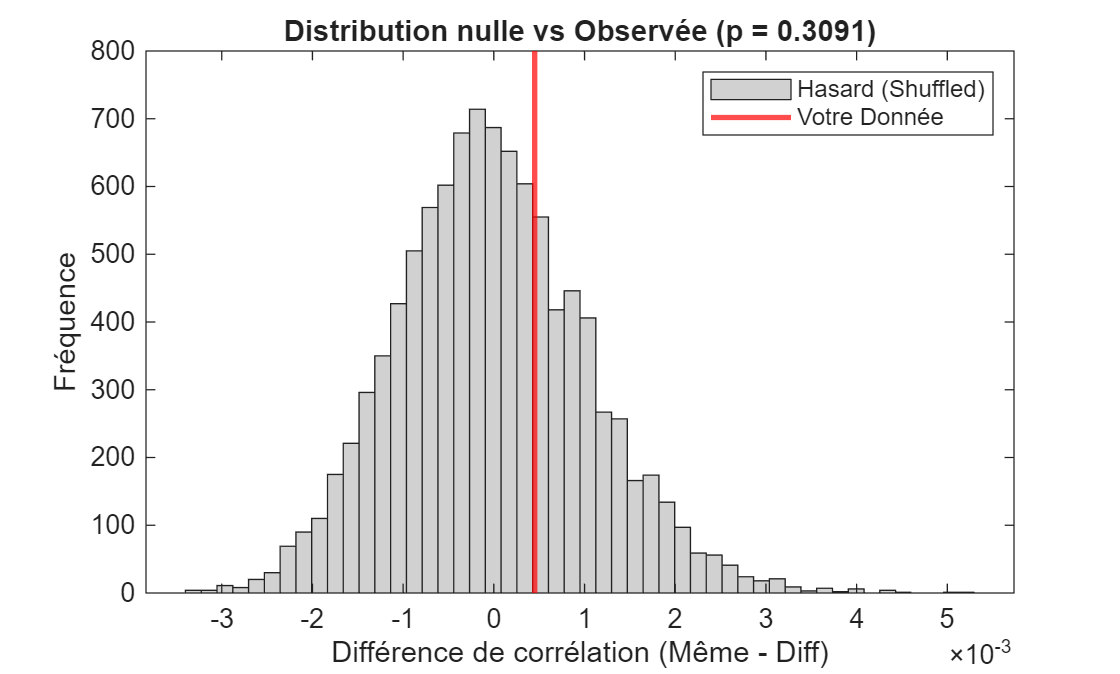


%% 4. Visualisation
figure;
histogram(diff_shuffled, 50, 'FaceColor', [.7 .7 .7]); hold on;
xline(diff_obs, 'r', 'LineWidth', 2);
xlabel('Différence de corrélation (Même - Diff)');
ylabel('Fréquence');
title(['Distribution nulle vs Observée (p = ' num2str(p_value) ')']);
legend('Hasard (Shuffled)', 'Votre Donnée');

return

%% ANALYSE PAR FENÊTRE GLISSANTE : PROFIL SPATIAL DE LA CORRÉLATION
% Objectif : Tracer l'évolution précise de la connectivité en fonction de la distance
% pour identifier la taille fonctionnelle des assemblées clonales.

%% 1. Paramètres de la Fenêtre Glissante
window_width = 10;  % Largeur de la fenêtre en µm (ex: +/- 20 µm autour du centre)
step_size    = 10;  % Pas d'avancement en µm (Résolution de la courbe)
max_dist     = 700; % Distance maximale à analyser
centers      = (window_width/2) : step_size : max_dist; % Centres des fenêtres

pixel_size = 1.37; % Calibration

%% 2. Préparation des Matrices (Si nécessaire)
if ~exist('All_Corr', 'var'), All_Corr = corrcoef(DF'); end
if ~exist('Dist_Mat', 'var')
    Coords_um = gcamp_centroid * pixel_size;
    Dist_Mat = squareform(pdist(Coords_um));
end

N_cells = size(All_Corr, 1);
mask_tri = triu(true(N_cells), 1); % Masque triangle supérieur (hors diagonale)

% Création des masques d'identité
Color_Row = colorcell(:);
Color_Col = colorcell(:)';
mask_same_global = (Color_Row == Color_Col) & mask_tri; % Paires Même Couleur
mask_diff_global = (Color_Row ~= Color_Col) & mask_tri; % Paires Différentes

%% 3. Boucle sur les Fenêtres (Sliding Window)
n_steps = length(centers);

% Initialisation des résultats
res_same_mean = nan(1, n_steps);
res_diff_mean = nan(1, n_steps);
res_same_sem  = nan(1, n_steps); % Erreur standard pour barres d'erreur
res_diff_sem  = nan(1, n_steps);
count_same    = nan(1, n_steps);

fprintf('Calcul du profil spatial (Fenêtre %d µm, Pas %d µm)...\n', window_width, step_size);

Calcul du profil spatial (Fenêtre 10 µm, Pas 10 µm)...


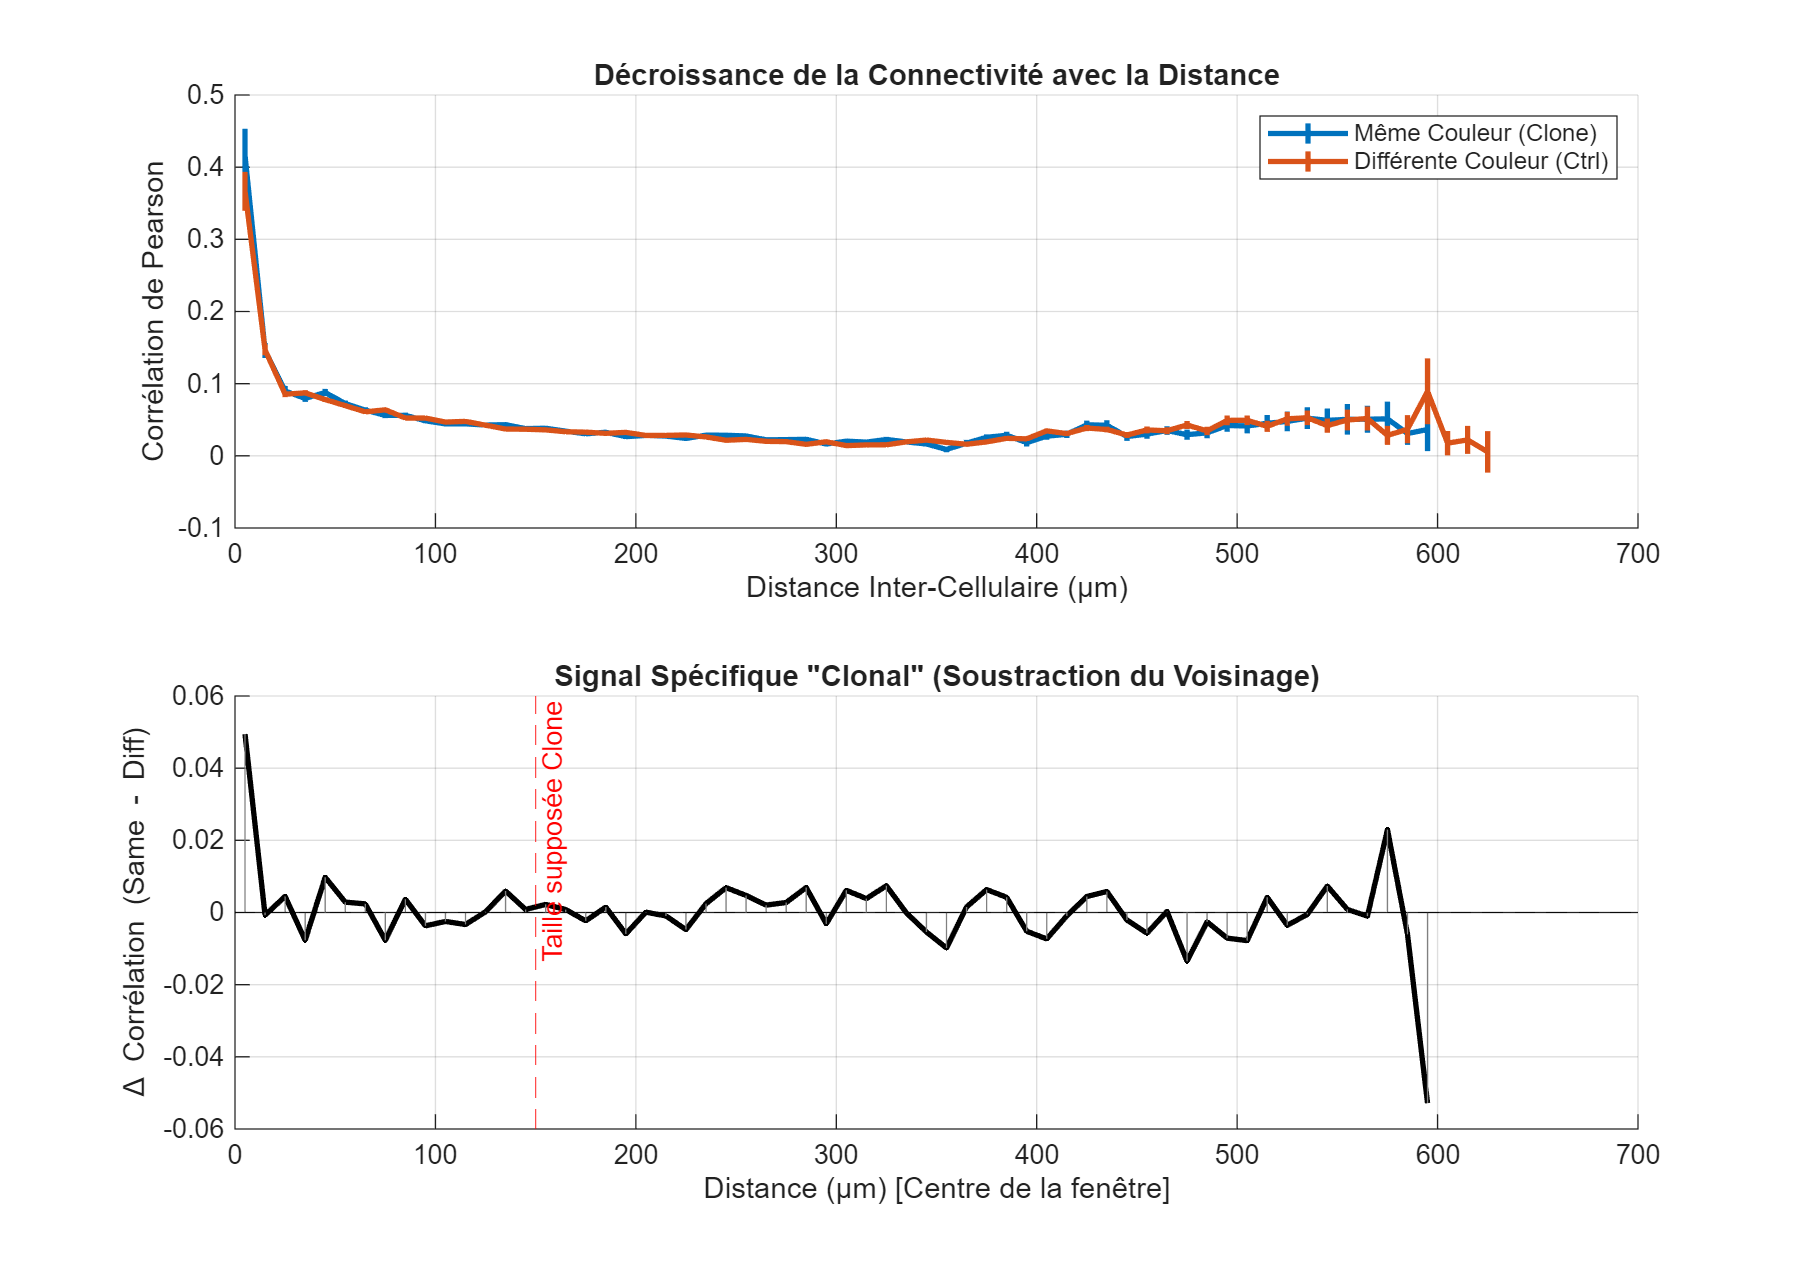


for k = 1:n_steps
    ct = centers(k);
    min_d = ct - window_width/2;
    max_d = ct + window_width/2;
    
    % Masque de distance pour la fenêtre actuelle (Intervalle strict)
    mask_dist_current = (Dist_Mat >= min_d) & (Dist_Mat < max_d);
    
    % --- GROUPE MEME COULEUR ---
    mask_s = mask_same_global & mask_dist_current;
    vals_s = All_Corr(mask_s);
    
    if numel(vals_s) > 5 % Sécurité si pas assez de paires
        res_same_mean(k) = mean(vals_s);
        res_same_sem(k)  = std(vals_s) / sqrt(numel(vals_s));
        count_same(k)    = numel(vals_s);
    end
    
    % --- GROUPE CONTROLE (DIFF COULEUR) ---
    mask_d = mask_diff_global & mask_dist_current;
    vals_d = All_Corr(mask_d);
    
    if numel(vals_d) > 5
        res_diff_mean(k) = mean(vals_d);
        res_diff_sem(k)  = std(vals_d) / sqrt(numel(vals_d));
    end
end

% Calcul du Delta (Signal Clonal pur)
delta_corr = res_same_mean - res_diff_mean;


%% 4. Affichage Graphique
figure('Color','w', 'Position', [100 100 1000 700], 'Name', 'Profil Spatial Clonale');

% --- Panel Haut : Les courbes brutes ---
subplot(2,1,1); hold on; grid on;
% Tracé avec zone d'erreur simple (shaded area serait mieux mais nécessite fonction externe)
errorbar(centers, res_same_mean, res_same_sem, 'LineWidth', 2, 'Color', [0 0.4470 0.7410], 'CapSize',0);
errorbar(centers, res_diff_mean, res_diff_sem, 'LineWidth', 2, 'Color', [0.8500 0.3250 0.0980], 'CapSize',0);

xlabel('Distance Inter-Cellulaire (µm)');
ylabel('Corrélation de Pearson');
title('Décroissance de la Connectivité avec la Distance');
legend({'Même Couleur (Clone)', 'Différente Couleur (Ctrl)'});
xlim([0 max_dist]);

% --- Panel Bas : La Différence (Le Signal d'Intérêt) ---
subplot(2,1,2); hold on; grid on;
plot(centers, delta_corr, 'k-', 'LineWidth', 2);
stem(centers, delta_corr, 'Color', [0.5 0.5 0.5], 'Marker', 'none'); % Tiges pour visualiser

yline(0, 'k--'); % Ligne zéro
xline(150, 'r--', 'Taille supposée Clone'); % Repère visuel

xlabel('Distance (µm) [Centre de la fenêtre]');
ylabel('\Delta Corrélation (Same - Diff)');
title('Signal Spécifique "Clonal" (Soustraction du Voisinage)');
xlim([0 max_dist]);


%% 5. Sauvegarde pour Analyse de Groupe
% C'est CES vecteurs qu'il faudra moyenner sur tous vos animaux plus tard
Results_Session.centers = centers;
Results_Session.delta   = delta_corr;
Results_Session.same    = res_same_mean;
Results_Session.diff    = res_diff_mean;

% save('Resultat_Session_X.mat', 'Results_Session');


## calcul correlation Pearson cellules chaque  couleur vs cellules couleurs différentes

%% 1. Préparation et Initialisation

N_perms = 10000;          % Nombre de permutations
All_Corr = corrcoef(DF'); % Matrice de corrélation globale (489x489)
N_cells_total = size(All_Corr, 1);

% Stockage des résultats
results = zeros(6, 2);    % [Différence_Observed, P_value]
shuf_history = zeros(N_perms, 6); % Pour stocker toutes les perms (pour le graph)

%fprintf('--- Lancement des tests par couleur (Permutations: %d) ---\n', N_perms);

%% 2. Boucle de calcul sur chaque couleur
for c = 1:6
    % --- A. Calcul Observé (Réalité) ---
    idx_target = find(colorcell == c);      % Indices des cellules de couleur C
    idx_other  = find(colorcell ~= c);      % Indices des autres
    
    % Sécurité : si pas assez de cellules, on passe
    if numel(idx_target) < 2
        results(c,:) = [NaN, NaN];
        fprintf('Couleur %d : Pas assez de cellules.\n', c);
        continue;
    end
    
    % Moyenne Intra (Triangle sup strict pour ne pas compter la diagonale)
    sub_corr_intra = All_Corr(idx_target, idx_target);
    mask_tri = triu(true(numel(idx_target)), 1);
    mean_intra = mean(sub_corr_intra(mask_tri));
    
    % Moyenne Inter (Rectangulaire, tout compte)
    sub_corr_inter = All_Corr(idx_target, idx_other);
    mean_inter = mean(sub_corr_inter(:));
    
    obs_diff = mean_intra - mean_inter;
    
    % --- B. Permutations (Hasard) ---
    count_sup = 0; % Compteur pour la p-value
    
    for k = 1:N_perms
        % On mélange : on tire au hasard N cellules pour être le "Faux Groupe C"
        rand_idx_target = randperm(N_cells_total, numel(idx_target));
        rand_idx_other = setdiff(1:N_cells_total, rand_idx_target);
        
        % Moyenne Intra (Faux groupe)
        shuf_intra_mat = All_Corr(rand_idx_target, rand_idx_target);
        shuf_mean_intra = mean(shuf_intra_mat(mask_tri));
        
        % Moyenne Inter (Faux groupe vs Reste)
        shuf_inter_mat = All_Corr(rand_idx_target, rand_idx_other);
        shuf_mean_inter = mean(shuf_inter_mat(:));
        
        shuf_diff = shuf_mean_intra - shuf_mean_inter;
        
        % STOCKAGE pour le graphique
        shuf_history(k, c) = shuf_diff;
        
        % Test statistique
        if shuf_diff >= obs_diff
            count_sup = count_sup + 1;
        end
    end
    
    % --- C. Résultats ---
    p_val = count_sup / N_perms;
    results(c, 1) = obs_diff;
    results(c, 2) = p_val;
    
    fprintf('Couleur %d : Diff = %.4f | P-value = %.4f ', c, obs_diff, p_val);
    if p_val < 0.05
        fprintf('(*) SIGNIFICATIF\n');
    else
        fprintf('\n');
    end
end

%% 3. Visualisation (Exemple pour la couleur la plus significative)
% On cherche automatiquement la couleur avec la p-value la plus basse (ou obs diff max)
[~, best_c] = max(results(:,1)); % Prend la couleur avec la plus grande différence observée

if ~isnan(results(best_c, 1))
    figure('Color', 'w', 'Name', 'Test de Permutation');
    
    % Histogramme de la distribution nulle
    h = histogram(shuf_history(:, best_c), 50, 'Normalization', 'probability');
    h.FaceColor = [0.7 0.7 0.7]; 
    h.EdgeColor = 'none';
    hold on;
    
    % Ligne de la valeur observée
    val_obs = results(best_c, 1);
    yl = ylim;
    line([val_obs val_obs], yl, 'Color', 'r', 'LineWidth', 2, 'LineStyle', '--');
    
    % Décoration
    xlabel('Différence de Corrélation (Intra - Inter)');
    ylabel('Probabilité');
    title(sprintf('Test de Permutation - Couleur %d\nDiff = %.4f, p = %.4f', ...
        best_c, val_obs, results(best_c, 2)));
    legend({'Distribution Aléatoire (Null)', 'Observé'}, 'Location', 'best');
    grid on; box off;
    
    fprintf('\nGraphique généré pour la couleur %d.\n', best_c);
end

%% 4. Visualisation : Grille 2x3 pour les 6 couleurs
figure('Name', 'Résultats Permutation par Couleur', 'Color', 'w', 'Position', [100, 100, 1200, 700]);

for c = 1:6
    subplot(2, 3, c); % Crée une grille de 2 lignes x 3 colonnes
    
    % Vérification si données valides
    if isnan(results(c, 1))
        title(sprintf('Couleur %d : Pas assez de données', c));
        continue;
    end
    
    % 1. Histogramme Gris (Null Distribution)
    h = histogram(shuf_history(:, c), 50, 'Normalization', 'probability');
    h.FaceColor = [0.7 0.7 0.7];
    h.EdgeColor = 'none';
    hold on;
    
    % 2. Ligne Rouge (Valeur Observée)
    val_obs = results(c, 1);
    yl = ylim; % Récupère la hauteur max actuelle
    line([val_obs val_obs], yl, 'Color', 'r', 'LineWidth', 2, 'LineStyle', '--');
    
    % 3. Titre et Style
    p_v = results(c, 2);
    if p_v < 0.05
        % Titre en gras ou avec étoile si significatif
        title(sprintf('Couleur %d (Significatif *)\np = %.4f', c, p_v), 'FontWeight', 'bold', 'Color', 'r');
    else
        title(sprintf('Couleur %d (n.s.)\np = %.4f', c, p_v), 'Color', 'k');
    end
    
    xlabel('Différence (Intra - Inter)');
    if mod(c, 3) == 1, ylabel('Probabilité'); end % Label Y juste sur la colonne de gauche
    
    grid on; box off;
end



## calcul correlation Spearman cellules chaque  couleur vs cellules couleurs différentes

%% 1. Préparation et Initialisation

N_perms = 10000;          % Nombre de permutations
All_Corr = corr(DF','Type','Spearman'); 
N_cells_total = size(All_Corr, 1);

% Stockage des résultats
results = zeros(6, 2);    % [Différence_Observed, P_value]
shuf_history = zeros(N_perms, 6); % Pour stocker toutes les perms (pour le graph)

%fprintf('--- Lancement des tests par couleur (Permutations: %d) ---\n', N_perms);

%% 2. Boucle de calcul sur chaque couleur
for c = 1:6
    % --- A. Calcul Observé (Réalité) ---
    idx_target = find(colorcell == c);      % Indices des cellules de couleur C
    idx_other  = find(colorcell ~= c);      % Indices des autres
    
    % Sécurité : si pas assez de cellules, on passe
    if numel(idx_target) < 2
        results(c,:) = [NaN, NaN];
        fprintf('Couleur %d : Pas assez de cellules.\n', c);
        continue;
    end
    
    % Moyenne Intra (Triangle sup strict pour ne pas compter la diagonale)
    sub_corr_intra = All_Corr(idx_target, idx_target);
    mask_tri = triu(true(numel(idx_target)), 1);
    mean_intra = mean(sub_corr_intra(mask_tri));
    
    % Moyenne Inter (Rectangulaire, tout compte)
    sub_corr_inter = All_Corr(idx_target, idx_other);
    mean_inter = mean(sub_corr_inter(:));
    
    obs_diff = mean_intra - mean_inter;
    
    % --- B. Permutations (Hasard) ---
    count_sup = 0; % Compteur pour la p-value
    
    for k = 1:N_perms
        % On mélange : on tire au hasard N cellules pour être le "Faux Groupe C"
        rand_idx_target = randperm(N_cells_total, numel(idx_target));
        rand_idx_other = setdiff(1:N_cells_total, rand_idx_target);
        
        % Moyenne Intra (Faux groupe)
        shuf_intra_mat = All_Corr(rand_idx_target, rand_idx_target);
        shuf_mean_intra = mean(shuf_intra_mat(mask_tri));
        
        % Moyenne Inter (Faux groupe vs Reste)
        shuf_inter_mat = All_Corr(rand_idx_target, rand_idx_other);
        shuf_mean_inter = mean(shuf_inter_mat(:));
        
        shuf_diff = shuf_mean_intra - shuf_mean_inter;
        
        % STOCKAGE pour le graphique
        shuf_history(k, c) = shuf_diff;
        
        % Test statistique
        if shuf_diff >= obs_diff
            count_sup = count_sup + 1;
        end
    end
    
    % --- C. Résultats ---
    p_val = count_sup / N_perms;
    results(c, 1) = obs_diff;
    results(c, 2) = p_val;
    
    fprintf('Couleur %d : Diff = %.4f | P-value = %.4f ', c, obs_diff, p_val);
    if p_val < 0.05
        fprintf('(*) SIGNIFICATIF\n');
    else
        fprintf('\n');
    end
end

%% 3. Visualisation (Exemple pour la couleur la plus significative)
% On cherche automatiquement la couleur avec la p-value la plus basse (ou obs diff max)
[~, best_c] = max(results(:,1)); % Prend la couleur avec la plus grande différence observée

if ~isnan(results(best_c, 1))
    figure('Color', 'w', 'Name', 'Test de Permutation');
    
    % Histogramme de la distribution nulle
    h = histogram(shuf_history(:, best_c), 50, 'Normalization', 'probability');
    h.FaceColor = [0.7 0.7 0.7]; 
    h.EdgeColor = 'none';
    hold on;
    
    % Ligne de la valeur observée
    val_obs = results(best_c, 1);
    yl = ylim;
    line([val_obs val_obs], yl, 'Color', 'r', 'LineWidth', 2, 'LineStyle', '--');
    
    % Décoration
    xlabel('Différence de Corrélation (Intra - Inter)');
    ylabel('Probabilité');
    title(sprintf('Test de Permutation - Couleur %d\nDiff = %.4f, p = %.4f', ...
        best_c, val_obs, results(best_c, 2)));
    legend({'Distribution Aléatoire (Null)', 'Observé'}, 'Location', 'best');
    grid on; box off;
    
    fprintf('\nGraphique généré pour la couleur %d.\n', best_c);
end

%% 4. Visualisation : Grille 2x3 pour les 6 couleurs
figure('Name', 'Résultats Permutation par Couleur', 'Color', 'w', 'Position', [100, 100, 1200, 700]);

for c = 1:6
    subplot(2, 3, c); % Crée une grille de 2 lignes x 3 colonnes
    
    % Vérification si données valides
    if isnan(results(c, 1))
        title(sprintf('Couleur %d : Pas assez de données', c));
        continue;
    end
    
    % 1. Histogramme Gris (Null Distribution)
    h = histogram(shuf_history(:, c), 50, 'Normalization', 'probability');
    h.FaceColor = [0.7 0.7 0.7];
    h.EdgeColor = 'none';
    hold on;
    
    % 2. Ligne Rouge (Valeur Observée)
    val_obs = results(c, 1);
    yl = ylim; % Récupère la hauteur max actuelle
    line([val_obs val_obs], yl, 'Color', 'r', 'LineWidth', 2, 'LineStyle', '--');
    
    % 3. Titre et Style
    p_v = results(c, 2);
    if p_v < 0.05
        % Titre en gras ou avec étoile si significatif
        title(sprintf('Couleur %d (Significatif *)\np = %.4f', c, p_v), 'FontWeight', 'bold', 'Color', 'r');
    else
        title(sprintf('Couleur %d (n.s.)\np = %.4f', c, p_v), 'Color', 'k');
    end
    
    xlabel('Différence (Intra - Inter)');
    if mod(c, 3) == 1, ylabel('Probabilité'); end % Label Y juste sur la colonne de gauche
    
    grid on; box off;
end


##  Pearson correlation / distance intervalle

%% PARAMÈTRES
dist_edges = [0:50:500]; % Vos intervalles de distance (µm)
pixel_size = 1.37; % REMPLACEZ par votre taille de pixel réelle (si coord en pixels)

% 1. Matrices Pré-calculées (Optimisation)
% Distance en microns
Coords_um = gcamp_centroid * pixel_size; 
Dist_Mat = squareform(pdist(Coords_um)); 

% Corrélation
All_Corr = corrcoef(DF');

N_cells = size(All_Corr, 1);

% Stockage des résultats : Structure ou Matrice 3D
% result_mean(Couleur, BinDistance)
n_bins = length(dist_edges) - 1;
res_mean = nan(6, n_bins);
res_sem  = nan(6, n_bins);
bin_centers = (dist_edges(1:end-1) + dist_edges(2:end)) / 2;

%fprintf('Calcul Couleur x Distance...\n');

%% 2. Boucle Double : Couleur -> Distance
for c = 1:6
    % Indices des cellules de cette couleur
    idx_c = find(colorcell == c);
    n_c = numel(idx_c);
    
    if n_c < 2
        continue; % Pas assez de cellules pour faire des paires
    end
    
    % On extrait les sous-matrices UNIQUEMENT pour cette couleur
    % (Corrélation entre rouges, Distance entre rouges)
    sub_corr = All_Corr(idx_c, idx_c);
    sub_dist = Dist_Mat(idx_c, idx_c);
    
    % Masque triangle sup pour ne pas compter deux fois
    mask_tri = triu(true(n_c), 1);
    
    % Boucle sur les bins de distance
    for k = 1:n_bins
        d_min = dist_edges(k);
        d_max = dist_edges(k+1);
        
        % Masque "Bonne Distance" pour cette couleur
        mask_d = (sub_dist >= d_min) & (sub_dist < d_max) & mask_tri;
        
        % Valeurs de corrélation correspondantes
        vals = sub_corr(mask_d);
        
        if ~isempty(vals)
            res_mean(c, k) = mean(vals);
            res_sem(c, k)  = std(vals) / sqrt(length(vals));
        else
            res_mean(c, k) = NaN; % Pas de paires à cette distance
        end
    end
end

%% 3. Visualisation : 6 Courbes sur un graphe
figure('Color', 'w', 'Position', [100 100 800 600]);
hold on;

% Palette de couleurs pour le plot (exemple)
plot_colors = {'r', 'g', 'b', 'c', 'm', 'y'}; % Adaptez à vos vraies couleurs
% Ou mieux : colors = [1 0 0; 0 1 0; ...];

for c = 1:6
    % On ne plot que si on a des données
    if all(isnan(res_mean(c,:))), continue; end
    
    % Courbe avec barres d'erreur
    errorbar(bin_centers, res_mean(c,:), res_sem(c,:), ...
        '-o', 'LineWidth', 2, 'CapSize', 0, ...
        'Color', plot_colors{c}, ...
        'DisplayName', sprintf('Couleur %d', c));
end

xlabel('Distance (\mum)');
ylabel('Corrélation Moyenne (r)');
title('Décroissance de la Corrélation par Distance et Couleur');
legend('Location', 'Best');
grid on;

%% 4. (Optionnel) Ajout de la courbe "Mélange" (Shuffle/Global) en noir pour comparer
% Cela permet de voir si une couleur est AU-DESSUS de la tendance générale
%% 4. (Optionnel) Ajout de la courbe "Global" CORRECTE
% On s'assure que tout est NxN
N = size(Dist_Mat, 1);       % Taille réelle basée sur la distance
mask_all_tri = triu(true(N), 1); % Recréation du masque triangle sup stricte à la bonne taille

global_means = nan(1, n_bins);

%fprintf('Calcul courbe globale...\n');

for k = 1:n_bins
    d_min = dist_edges(k);
    d_max = dist_edges(k+1);
    
    % Masque combiné : Bonne distance ET Triangle Supérieur
    mask_d_all = (Dist_Mat >= d_min) & (Dist_Mat < d_max) & mask_all_tri;
    
    % Extraction des valeurs
    vals_all = All_Corr(mask_d_all);
    
    if ~isempty(vals_all)
        global_means(k) = mean(vals_all);
    else
        global_means(k) = NaN;
    end
end

% Plot de la ligne noire
plot(bin_centers, global_means, 'k--', 'LineWidth', 3, 'DisplayName', 'Global (Toutes paires)');
legend('Location', 'Best'); % Mise à jour de la légende
%% Test de Significativité (Permutation par Bin de Distance)
N_perms = 1000; % 1000 permutations suffit pour visualiser l'enveloppe
conf_level = 0.95; % Seuil de confiance (95%)

% 1. Préparation des structures
% On va stocker les min/max de la distribution nulle pour chaque bin
null_envelope_low = zeros(1, n_bins);
null_envelope_high = zeros(1, n_bins);

% On a besoin de All_Corr, Dist_Mat, n_bins, dist_edges
% (Assurez-vous que les tailles sont bien corrigées comme vu précédemment)
N = size(All_Corr, 1);
mask_tri = triu(true(N), 1);

%fprintf('Calcul de l''enveloppe de confiance globale (%d perms)...\n', N_perms);

% 2. Boucle sur les Bins de Distance (On traite bin par bin)
for k = 1:n_bins
    d_min = dist_edges(k);
    d_max = dist_edges(k+1);
    
    % Masque des paires à cette distance (fixe pour toutes les perms)
    mask_d_bin = (Dist_Mat >= d_min) & (Dist_Mat < d_max) & mask_tri;
    
    % Nombre de paires dans ce bin
    idx_pairs = find(mask_d_bin);
    n_pairs_bin = numel(idx_pairs);
    
    if n_pairs_bin < 10
        null_envelope_low(k) = NaN; 
        null_envelope_high(k) = NaN;
        continue; 
    end
    
    % Pour ce bin, quelle est la corrélation moyenne qu'on obtiendrait
    % si on prenait des sous-groupes de taille similaire au hasard ?
    % -> C'est subtil ici : on veut tester "Est-ce que CE GROUPE (Couleur X) est spécial ?"
    % L'approche la plus simple est de permuter les couleurs.
    
    % Mais pour tracer l'enveloppe globale "Grise" autour de la courbe noire,
    % on peut juste bootstraper les corrélations de ce bin.
    
    vals_real = All_Corr(mask_d_bin);
    shuf_means = zeros(N_perms, 1);
    
    % On tire au hasard N_sample paires dans ce bin
    % (N_sample = taille moyenne d'un groupe couleur dans ce bin ? Difficile à dire)
    % APPROCHE PLUS ROBUSTE :
    % On permute les identités des cellules et on recalcule les courbes "Même Couleur".
    
    % On va faire une permutation globale des couleurs
end

% --- REPRISE DE LA LOGIQUE : Permutation des Couleurs ---
% C'est le seul moyen de garder la structure spatiale intacte.
% On mélange les couleurs, et on regarde les courbes "Même couleur" obtenues.

shuf_res_mean = zeros(N_perms, 6, n_bins); % [Perms x Couleurs x Bins]

wb = waitbar(0, 'Permutations en cours...');

for p = 1:N_perms
    % Mélange des couleurs
    shuf_colors = colorcell(randperm(N));
    
    for c = 1:6
        % Indices "Faux Rouge", "Faux Vert"...
        idx_c = find(shuf_colors == c);
        
        if numel(idx_c) < 2, continue; end
        
        sub_corr = All_Corr(idx_c, idx_c);
        sub_dist = Dist_Mat(idx_c, idx_c);
        mask_sub_tri = triu(true(numel(idx_c)), 1);
        
        for k = 1:n_bins
            d_min = dist_edges(k);
            d_max = dist_edges(k+1);
            
            mask_d = (sub_dist >= d_min) & (sub_dist < d_max) & mask_sub_tri;
            vals = sub_corr(mask_d);
            
            if ~isempty(vals)
                shuf_res_mean(p, c, k) = mean(vals);
            else
                shuf_res_mean(p, c, k) = NaN;
            end
        end
    end
    
    if mod(p, 50) == 0, waitbar(p/N_perms, wb); end
end
close(wb);

%% 3. Calcul des P-values et Affichage
% Pour chaque couleur et chaque bin, on compare la vraie moyenne (res_mean)
% à la distribution des 1000 moyennes mélangées (shuf_res_mean).

p_values = nan(6, n_bins);
% Seuil pour dire "Significatif" (bilatéral : <0.025 ou >0.975)
alpha = 0.05; 

for c = 1:6
    for k = 1:n_bins
        obs = res_mean(c, k);
        if isnan(obs), continue; end
        
        distrib = shuf_res_mean(:, c, k);
        distrib = distrib(~isnan(distrib)); % Enlever les NaNs
        
        if isempty(distrib), continue; end
        
        % P-value (Proportion des permutations qui sont PLUS EXTRÊMES que l'obs)
        % On teste "Supérieur" (Activation) et "Inférieur" (Inhibition)
        
        % Calcul p-value empirique (Two-tailed)
        % On regarde où se situe obs dans la distribution triée
        n_better = sum(distrib >= obs);
        p_val_sup = n_better / numel(distrib); % Test "Est-ce plus grand ?"
        
        n_worse = sum(distrib <= obs);
        p_val_inf = n_worse / numel(distrib);  % Test "Est-ce plus petit ?"
        
        % On prend la plus petite des deux * 2 (Correction two-tailed simple)
        p_values(c, k) = min(p_val_sup, p_val_inf) * 2;
    end
end

%% 4. Ajout des Etoiles sur le Graphique Existant
% Assurez-vous d'avoir la figure ouverte (celle avec les courbes colorées)
figure(gcf); % Rappelle la figure active

for c = 1:6
    for k = 1:n_bins
        pv = p_values(c, k);
        
        if ~isnan(pv) && pv < 0.05
            % Coordonnées du point
            x = bin_centers(k);
            y = res_mean(c, k);
            
            % Ajout d'une étoile
            % Décalage vertical pour ne pas écraser le point
            offset = 0.01 * sign(y); 
            % text(x, y + offset, '*', ...
            %     'Color', plot_colors{c}, 'FontSize', 20, ...
            %     'HorizontalAlignment', 'center');
                        text(x, y + offset, '*', ...
                'Color', 'k', 'FontSize', 20, ...
                'HorizontalAlignment', 'center');
        end
    end
end
fprintf('Etoiles ajoutées pour p < 0.05.\n');
%% 5. Rapport Écrit des Résultats Significatifs
fprintf('\n======================================================\n');
fprintf(' RAPPORT STATISTIQUE DÉTAILLÉ (Test Permutation)\n');
fprintf('======================================================\n');
fprintf('Seuil de significativité : p < 0.05 (*)\n\n');

for c = 1:6
    fprintf('--- COULEUR %d ---\n', c);
    
    % En-tête du tableau pour cette couleur
    fprintf('%-15s | %-10s | %-10s | %-10s\n', 'Distance (µm)', 'Corr (r)', 'P-value', 'Signif.');
    fprintf('%s\n', repmat('-', 1, 55));
    
    has_significant_points = false;
    
    for k = 1:n_bins
        d_label = sprintf('%d-%d', dist_edges(k), dist_edges(k+1));
        obs_val = res_mean(c, k);
        p_val   = p_values(c, k);
        
        if isnan(obs_val) || isnan(p_val)
            res_str = 'N/A';
            sig_str = '';
        else
            if p_val < 0.001
                sig_str = '***';
                has_significant_points = true;
            elseif p_val < 0.01
                sig_str = '**';
                has_significant_points = true;
            elseif p_val < 0.05
                sig_str = '*';
                has_significant_points = true;
            else
                sig_str = 'n.s.';
            end
            
            % Affichage de la ligne
            fprintf('%-15s | %8.4f   | %8.4f   | %s\n', ...
                d_label, obs_val, p_val, sig_str);
        end
    end
    
    if ~has_significant_points
        fprintf('  (Aucun point significatif pour cette couleur)\n');
    end
    fprintf('\n');
end
fprintf('======================================================\n');

## ANALYSE CUMULATIVE (Pearson Corrélation vs Distance Max) méthode1

% Paramètres
cum_dists = [10, 20, 30, 40, 50, 100, 150, 200, 250,300,400,500]; 
n_cum = length(cum_dists);
N_perms = 2000; 
pixel_size = 1.37;

% 1. Matrices Pré-calculées (Optimisation)
% Distance en microns
Coords_um = gcamp_centroid * pixel_size; 
Dist_Mat = squareform(pdist(Coords_um)); 

% Corrélation
All_Corr = corrcoef(DF');

% Stockage
res_cum_obs = nan(6, n_cum);   
res_cum_pval = nan(6, n_cum);  

N_cells = size(All_Corr, 1);
mask_tri = triu(true(N_cells), 1);

%% 1. Boucle de Calcul
for c = 1:6
    idx_c = find(colorcell == c);
    n_c = numel(idx_c);
    
    if n_c < 2, continue; end
    
    sub_corr = All_Corr(idx_c, idx_c);
    sub_dist = Dist_Mat(idx_c, idx_c);
    mask_sub_tri = triu(true(n_c), 1);
    
    % A. Valeurs Observées
    for k = 1:n_cum
        d_limit = cum_dists(k);
        mask_d = (sub_dist < d_limit) & mask_sub_tri;
        vals = sub_corr(mask_d);
        if ~isempty(vals)
            res_cum_obs(c, k) = mean(vals);
        end
    end
    
    % B. Permutations
    count_better = zeros(1, n_cum);
    count_worse  = zeros(1, n_cum);
    
    for p = 1:N_perms
        rand_idx = randperm(N_cells, n_c);
        shuf_corr = All_Corr(rand_idx, rand_idx);
        shuf_dist = Dist_Mat(rand_idx, rand_idx);
        
        for k = 1:n_cum
            d_limit = cum_dists(k);
            mask_shuf = (shuf_dist < d_limit) & mask_sub_tri;
            vals_shuf = shuf_corr(mask_shuf);
            
            if ~isempty(vals_shuf)
                m_shuf = mean(vals_shuf);
                if m_shuf >= res_cum_obs(c, k), count_better(k) = count_better(k) + 1; end
                if m_shuf <= res_cum_obs(c, k), count_worse(k) = count_worse(k) + 1; end
            end
        end
    end
    
    % P-values
    for k = 1:n_cum
        p_sup = count_better(k) / N_perms;
        p_inf = count_worse(k) / N_perms;
        res_cum_pval(c, k) = min(p_sup, p_inf) * 2; 
    end
    fprintf('Couleur %d traitée.\n', c);
end

%% 2. Tableau des Résultats
fprintf('\n======================================================\n');
fprintf(' RÉSULTATS CUMULATIFS (Distance < X µm)\n');
fprintf('======================================================\n');
for c = 1:6
    fprintf('--- COULEUR %d ---\n', c);
    for k = 1:n_cum
        if isnan(res_cum_obs(c,k)), continue; end
        pv = res_cum_pval(c, k);
        sig = 'n.s.';
        if pv < 0.001, sig = '***'; elseif pv < 0.01, sig = '**'; elseif pv < 0.05, sig = '*'; end
        fprintf('< %-13d | %8.4f   | %8.4f   | %s\n', cum_dists(k), res_cum_obs(c,k), pv, sig);
    end
    fprintf('\n');
end

%% 3. Graphique Résumé (Couleurs Spécifiques)
figure('Color', 'w', 'Name', 'Analyse Cumulative');
hold on;

% Définition manuelle des couleurs : R, G, B, Y, M, C
my_colors = [
    1 0 0;   % 1 = Rouge
    0 1 0;   % 2 = Vert
    0 0 1;   % 3 = Bleu
    1 1 0;   % 4 = Jaune
    1 0 1;   % 5 = Magenta
    0 1 1    % 6 = Cyan
];

for c = 1:6
    % Vérif si données existent
    if all(isnan(res_cum_obs(c,:))), continue; end
    
    % Trace la ligne
    plot(cum_dists, res_cum_obs(c,:), '-o', 'LineWidth', 2, ...
        'Color', my_colors(c,:), ...
        'MarkerFaceColor', my_colors(c,:), ... % Remplit les ronds
        'DisplayName', sprintf('Couleur %d', c));
    
    % Ajout d'étoiles si signif
    idx_sig = find(res_cum_pval(c,:) < 0.05);
    if ~isempty(idx_sig)
        % On décale un peu l'étoile pour qu'elle soit lisible
        plot(cum_dists(idx_sig), res_cum_obs(c, idx_sig) + 0.005, 'p', ... % 'p' = pentagram (étoile)
            'Color', 'k', ... % Etoile noire pour bien contraster sur le jaune/cyan
            'MarkerFaceColor', my_colors(c,:), ...
            'MarkerSize', 12, ...
            'HandleVisibility', 'off'); 
    end
end

xlabel('Distance Maximale (< µm)');
ylabel('Corrélation Moyenne cumulée');
title('Analyse Cumulative par Couleur');
legend('Location', 'BestOutside'); % Légende à l'extérieur pour ne pas cacher les courbes
grid on;

## ANALYSE CUMULATIVE (Pearson Corrélation vs Distance Max) méthode2 JC

%% Paramètres
cum_dists = [10, 20, 30, 40, 50, 100, 150, 200, 250, 300, 400, 500];
n_cum = length(cum_dists);
N_perms = 2000;
pixel_size = 1.37;

% 1. Matrices Pré-calculées
Coords_um = gcamp_centroid * pixel_size;
Dist_Mat = squareform(pdist(Coords_um));
All_Corr = corrcoef(DF');

N_cells = size(All_Corr, 1);
mask_tri_all = triu(true(N_cells), 1); % Masque triangle sup global

% Stockage
res_cum_obs = nan(6, n_cum);
res_cum_pval = nan(6, n_cum);
obs_counts = nan(6, n_cum); % Pour stocker combien de paires on a trouvé

%% 1. Boucle de Calcul
fprintf('Démarrage de l''analyse par PAIRES (Pair-Matching)...\n');

for c = 1:6
    idx_c = find(colorcell == c);
    n_c = numel(idx_c);
    
    if n_c < 2
        fprintf('Couleur %d sautée (pas assez de cellules).\n', c);
        continue; 
    end

    % --- ÉTAPE A : Identifier les paires de "Ma Couleur" ---
    % On crée une sous-matrice booléenne pour repérer où sont les paires (c,c) dans la grande matrice
    is_my_color = false(N_cells, 1);
    is_my_color(idx_c) = true;
    
    % Matrice "Outer Product" : true si i et j sont tous les deux de la couleur c
    mask_my_color_pairs = (is_my_color & is_my_color'); 
    
    % Masque des "Autres" paires (Pool de contrôle)
    % Ici on décide : le contrôle = toutes les paires qui NE SONT PAS (Rouge-Rouge)
    % Cela inclut (Rouge-Vert), (Bleu-Bleu), (Vert-Jaune), etc.
    % C'est le plus robuste : "Mes paires vs Le Reste du monde"
    mask_control_pool = (~mask_my_color_pairs) & mask_tri_all;
    
    % On affine le masque de "Ma couleur" avec le triangle sup
    mask_my_color_pairs = mask_my_color_pairs & mask_tri_all;

    for k = 1:n_cum
        d_limit = cum_dists(k);
        
        % 1. Mes paires réelles (Distance < d ET Couleur == c)
        mask_obs = mask_my_color_pairs & (Dist_Mat < d_limit);
        vals_obs = All_Corr(mask_obs);
        n_obs = numel(vals_obs);
        obs_counts(c, k) = n_obs; % On garde une trace
        
        % Si on n'a aucune paire à cette distance, impossible de calculer quoi que ce soit
        if n_obs == 0
            res_cum_obs(c, k) = NaN;
            res_cum_pval(c, k) = NaN;
            continue;
        end
        
        res_cum_obs(c, k) = mean(vals_obs);

        % 2. Le Pool de Contrôle (Distance < d ET Pas mes paires)
        mask_pool = mask_control_pool & (Dist_Mat < d_limit);
        pool_vals = All_Corr(mask_pool);
        n_pool = numel(pool_vals);

        % --- VÉRIFICATION DE FAISABILITÉ ---
        % On ne peut pas tirer 50 paires au hasard si le pool n'en contient que 10
        if n_pool < n_obs
            % Cas impossible : Pas assez de "paires autres" à cette distance pour comparer
            res_cum_pval(c, k) = NaN;
            continue; 
        end

        % 3. Permutations (Tirage aléatoire dans le pool)
        count_better = 0;
        count_worse = 0;
        
        % On utilise datasample pour aller vite (nécessite Statistics Toolbox)
        % Sinon on peut utiliser randperm
        for p = 1:N_perms
            % On tire 'n_obs' valeurs au hasard dans le pool
            shuf_vals = datasample(pool_vals, n_obs, 'Replace', false);
            
            m_shuf = mean(shuf_vals);
            
            if m_shuf >= res_cum_obs(c, k), count_better = count_better + 1; end
            if m_shuf <= res_cum_obs(c, k), count_worse = count_worse + 1; end
        end
        
        % P-values
        p_sup = count_better / N_perms;
        p_inf = count_worse / N_perms;
        res_cum_pval(c, k) = min(p_sup, p_inf) * 2;
    end
    %fprintf('Couleur %d traitée.\n', c);
end

%% 2. Tableau des Résultats
% fprintf('\n======================================================\n');
% fprintf(' RÉSULTATS (Pair-Matching: Mes Paires vs Paires Hétérogènes)\n');
% fprintf('======================================================\n');
for c = 1:6
    fprintf('--- COULEUR %d ---\n', c);
    for k = 1:n_cum
        dist = cum_dists(k);
        obs = res_cum_obs(c,k);
        pv = res_cum_pval(c, k);
        n_p = obs_counts(c, k);
        
        if isnan(obs)
             fprintf('< %-3d µm | (Aucune paire trouvée)\n', dist);
             continue;
        end
        
        if isnan(pv)
             fprintf('< %-3d µm | Obs: %6.4f (N=%d) | Pas assez de données de contrôle\n', dist, obs, n_p);
             continue;
        end

        sig = 'n.s.';
        if pv < 0.001, sig = '***'; elseif pv < 0.01, sig = '**'; elseif pv < 0.05, sig = '*'; end
        
        fprintf('< %-3d µm | Obs: %6.4f (N=%-3d) | p: %6.4f | %s\n', dist, obs, n_p, pv, sig);
    end
    fprintf('\n');
end


%% 3. Graphique Résumé (Couleurs Spécifiques)


% Définition manuelle des couleurs : R, G, B, Y, M, C
my_colors = [
    1 0 0;   % 1 = Rouge
    0 1 0;   % 2 = Vert
    0 0 1;   % 3 = Bleu
    1 1 0;   % 4 = Jaune
    1 0 1;   % 5 = Magenta
    0 1 1    % 6 = Cyan
];

for c = 1:6
    figure('Color', 'w', 'Name', 'Analyse Cumulative');
    hold on;
    % Vérif si données existent
    if all(isnan(res_cum_obs(c,:))), continue; end
    
    % Trace la ligne
    plot(cum_dists, res_cum_obs(c,:), '-o', 'LineWidth', 2, ...
        'Color', my_colors(c,:), ...
        'MarkerFaceColor', my_colors(c,:), ... % Remplit les ronds
        'DisplayName', sprintf('Couleur %d', c));
    hold on
    % Ajout d'étoiles si signif
    idx_sig = find(res_cum_pval(c,:) < 0.05);
    if ~isempty(idx_sig)
        % On décale un peu l'étoile pour qu'elle soit lisible
        plot(cum_dists(idx_sig), res_cum_obs(c, idx_sig) + 0.025, 'p', ... % 'p' = pentagram (étoile)
            'Color', 'k', ... % Etoile noire pour bien contraster sur le jaune/cyan
            'MarkerFaceColor', my_colors(c,:), ...
            'MarkerSize', 12, ...
            'HandleVisibility', 'off'); 
    end
    xlabel('Distance Maximale (< µm)');
    ylabel('Corrélation Moyenne cumulée');
    title('Analyse Cumulative par Couleur');
    legend('Location', 'BestOutside'); % Légende à l'extérieur pour ne pas cacher les courbes
    grid on;
    hold off
    
    ylim([0 1]); % Mettre l'échelle de l'ordonnée à 1
end

% xlabel('Distance Maximale (< µm)');
% ylabel('Corrélation Moyenne cumulée');
% title('Analyse Cumulative par Couleur');
% legend('Location', 'BestOutside'); % Légende à l'extérieur pour ne pas cacher les courbes
% grid on;

ANALYSE POOLÉE : TOUTES Paires Même Couleur vs TOUTES Paires Différentes Spearman

% Objectif : Voir si, globalement, "qui se ressemble s'assemble" fonctionnellement
% en contrôlant rigoureusement la distance.

%% 1. Paramètres & Initialisation
cum_dists = [10, 20, 30, 40, 50, 100, 150, 200, 250, 300, 400, 500];
n_cum = length(cum_dists);
N_perms = 10000; % On peut augmenter car on ne fait le calcul qu'une fois
pixel_size = 1.37;

% Calcul des matrices (si pas déjà fait)
%if ~exist('All_Corr', 'var')
   % All_Corr = corrcoef(DF');
    All_Corr = corr(DF', 'Type', 'Spearman'); 
%end

if ~exist('Dist_Mat', 'var')
    Coords_um = gcamp_centroid * pixel_size;
    Dist_Mat = squareform(pdist(Coords_um));
end

N_cells = size(All_Corr, 1);
mask_tri = triu(true(N_cells), 1); % Triangle supérieur strict

%% 2. Création des "Mega-Masques"
%fprintf('Construction des masques globaux...\n');

% Matrice d'identité des couleurs (i,j)
Color_Row = colorcell(:);         % Colonne
Color_Col = colorcell(:)';        % Ligne

% Masque 1 : Paires de MÊME couleur (Diagonale par blocs implicite)
% Ex: Rouge-Rouge OU Vert-Vert OU Bleu-Bleu...
mask_same_global = (Color_Row == Color_Col) & mask_tri;

% Masque 2 : Paires de COULEUR DIFFÉRENTE
% Ex: Rouge-Vert OU Bleu-Jaune...
mask_diff_global = (Color_Row ~= Color_Col) & mask_tri;

%% 3. Boucle sur les distances cumulatives
res_obs = nan(1, n_cum);
res_pval = nan(1, n_cum);
count_same = nan(1, n_cum);
count_diff = nan(1, n_cum);

%fprintf('Lancement de l''analyse poolée par distance...\n');

for k = 1:n_cum
    d_limit = cum_dists(k);
    
    % --- A. GROUPE TEST (Même Couleur) ---
    % On prend toutes les paires "Same" qui sont aussi proches que d_limit
    mask_current_same = mask_same_global & (Dist_Mat < d_limit);
    vals_same = All_Corr(mask_current_same);
    n_s = numel(vals_same);
    count_same(k) = n_s;
    
    if n_s < 5
        res_obs(k) = NaN; res_pval(k) = NaN;
        continue;
    end
    
    obs_mean = mean(vals_same);
    res_obs(k) = obs_mean;
    
    % --- B. GROUPE CONTRÔLE (Couleur Différente) ---
    % On prend toutes les paires "Diff" qui sont aussi proches que d_limit
    mask_current_diff = mask_diff_global & (Dist_Mat < d_limit);
    vals_diff = All_Corr(mask_current_diff);
    n_d = numel(vals_diff);
    count_diff(k) = n_d;
    
    if n_d < n_s
        fprintf('Attention à %d µm : Pas assez de paires différentes pour contrôler.\n', d_limit);
        res_pval(k) = NaN;
        continue;
    end
    
    % --- C. PERMUTATIONS (Bootstrap) ---
    % Question : Si je tire n_s paires au hasard parmi les paires "Différentes"
    % (qui sont à la même distance), quelle corrélation j'obtiens ?
    
    perms_means = zeros(N_perms, 1);
    
    % Version vectorisée rapide si Statistics Toolbox dispo (datasample)
    % Sinon boucle classique
    for p = 1:N_perms
        perms_means(p) = mean(datasample(vals_diff, n_s, 'Replace', false));
    end
    
    % Calcul P-value (Combien de fois le hasard "différent" bat l'observé "same" ?)
    % Test unilatéral (On s'attend à Same > Diff)
    count_better = sum(perms_means >= obs_mean);
    res_pval(k) = count_better / N_perms;
    
    fprintf('.'); % Barre de progression
end
fprintf('\nCalcul terminé.\n');

%% 4. Affichage des Résultats
fprintf('\n==================================================================\n');
fprintf(' RÉSULTATS POOLÉS : "Homotypique" vs "Hétérotypique" par Distance\n');
fprintf('==================================================================\n');
fprintf('%-10s | %-10s | %-10s | %-10s | %-10s\n', 'Dist (<)', 'Obs(Same)', 'N(Same)', 'p-val', 'Sig');
fprintf('------------------------------------------------------------------\n');

for k = 1:n_cum
    if isnan(res_obs(k)), continue; end
    
    d = cum_dists(k);
    obs = res_obs(k);
    pv = res_pval(k);
    ns = count_same(k);
    
    sig = 'n.s.';
    if pv < 0.001, sig = '***'; elseif pv < 0.01, sig = '**'; elseif pv < 0.05, sig = '*'; end
    
    fprintf('%-3d µm      | %7.4f    | %-5d      | %7.4f    | %s\n', ...
        d, obs, ns, pv, sig);
end

%% 5. Graphique Rapide (Optionnel)
figure('Color','w', 'Name', 'Analyse Poolée');
yyaxis left
plot(cum_dists, res_obs, '-o', 'LineWidth', 2);
ylabel('Corrélation Moyenne (Paires Même Couleur)');
xlabel('Distance Cumulative (< µm)');

yyaxis right
bar(cum_dists, -log10(res_pval + 1e-4), 'FaceAlpha', 0.3);
ylabel('-log10(p-value)');
yline(-log10(0.05), '--r', 'Seuil 0.05');
title('Force de la connectivité "Même Couleur" vs Distance');
legend({'Corrélation Obs', 'Significativité'}, 'Location', 'SouthEast');

%% VISUALISATION DES TRACES : PAIRES PROCHES DE MÊME COULEUR
% Paramètres à choisir
target_color = 6;        % Quelle couleur regarder ? (ex: 1 = Rouge)
max_dist_visu = 50;      % Distance max en µm
max_pairs_to_plot = 5;   % Combien de paires max on veut voir ?

% Récupération des indices
idx_c = find(colorcell == target_color);
n_c = numel(idx_c);

if n_c < 2
    error('Pas assez de cellules pour cette couleur.');
end

% Sous-matrices
sub_dist = Dist_Mat(idx_c, idx_c);
% On ne garde que le triangle sup pour avoir les paires uniques
mask_tri_local = triu(true(n_c), 1);

% Trouver les paires qui satisfont la condition de distance
[row, col] = find((sub_dist < max_dist_visu) & mask_tri_local);

n_found = length(row);
fprintf('Trouvé %d paires de couleur %d à distance < %d µm.\n', n_found, target_color, max_dist_visu);

if n_found == 0
    error('Aucune paire proche trouvée pour cette couleur.');
end

% Limitation du nombre de plots pour ne pas faire exploser l'écran
n_to_show = min(n_found, max_pairs_to_plot);

figure('Name', sprintf('Traces Paires Proches - Couleur %d', target_color), 'Color', 'w');

for k = 1:n_to_show
    % Indices locaux -> Indices globaux
    idx1 = idx_c(row(k));
    idx2 = idx_c(col(k));
    
    % Récupération des traces
    trace1 = DF(idx1, :);
    trace2 = DF(idx2, :);
    
    % Calcul de corrélation de cette paire spécifique
    r_pair = corr(trace1', trace2');
    d_pair = sub_dist(row(k), col(k));
    
    % Création du subplot
    subplot(n_to_show, 1, k);
    
    % Plot Trace 1 (Noir)
    plot(trace1, 'k'); hold on;
    % Plot Trace 2 (Rouge/Couleur cible) - On décale vers le haut pour lisibilité
    offset = max(trace1) - min(trace2) + 0.5; % Décalage dynamique
    plot(trace2 + offset, 'r');
    
    % Esthétique
    title(sprintf('Paire #%d (Cell %d & %d) | Dist = %.1f µm | r = %.2f', ...
        k, idx1, idx2, d_pair, r_pair));
    axis tight;
    if k < n_to_show
        set(gca, 'XTick', []); % Enlever l'axe X sauf pour le dernier
    end
    ylabel('dF/F');
end

xlabel('Temps (frames)');
sgtitle(sprintf('Exemples de Paires Proches (<%dµm) - Couleur %d', max_dist_visu, target_color));



%% 4. Tableau Récapitulatif avec N dans la Console
%fprintf('\n=== TABLEAU AVEC NOMBRE DE PAIRES ===\n');
for c = 1:6
    idx_c = find(colorcell == c);
    n_c = numel(idx_c);
    
    % Recalcul masque pour cette couleur
    sub_dist = Dist_Mat(idx_c, idx_c);
    mask_tri_local = triu(true(n_c), 1);
    
    fprintf('--- COULEUR %d ---\n', c);
    fprintf('%-10s | %-6s | %-8s | %-6s\n', 'Dist <', 'N_pair', 'Corr', 'Sig');
    
    for k = 1:n_cum
        d_lim = cum_dists(k);
        n_p = sum(sum((sub_dist < d_lim) & mask_tri_local)); % Compte exact
        
        obs = res_cum_obs(c, k);
        pv = res_cum_pval(c, k);
        
        sig = '';
        if pv<0.05, sig='*'; end
        if pv<0.01, sig='**'; end
        
        if ~isnan(obs)
            fprintf('%-10d | %-6d | %8.4f | %s\n', d_lim, n_p, obs, sig);
        end
    end
    fprintf('\n');
end


%% GRAPHIQUE FINAL : TOUS LES NOMBRES DE CELLULES AFFICHÉS
figure('Color', 'w', 'Name', 'Analyse Cumulative + Tous N', 'Position', [100 100 1000 600]);
hold on;

my_colors = [1 0 0; 0 1 0; 0 0 1; 1 1 0; 1 0 1; 0 1 1]; % R, G, B, Y, M, C
legend_entries = {}; 
h_plots = [];

for c = 1:6
    % Vérif si données existent
    if all(isnan(res_cum_obs(c,:))), continue; end
    
    % --- COMPTAGE EXACT CELLULES UNIQUES ---
    idx_c = find(colorcell == c);
    n_c = numel(idx_c);
    sub_dist = Dist_Mat(idx_c, idx_c);
    
    cells_counts = zeros(1, n_cum);
    for k = 1:n_cum
        d_limit = cum_dists(k);
        adj = (sub_dist < d_limit);
        adj(logical(eye(n_c))) = 0; 
        cells_counts(k) = sum(sum(adj, 2) > 0);
    end
    
    % --- TRACÉ COURBE ---
    hp = plot(cum_dists, res_cum_obs(c,:), '-o', 'LineWidth', 1.5, ...
        'Color', my_colors(c,:), 'MarkerFaceColor', my_colors(c,:));
    h_plots(end+1) = hp;
    legend_entries{end+1} = sprintf('Couleur %d', c);
    
    % --- AFFICHAGE DE n=... POUR CHAQUE POINT ---
    for k = 1:n_cum
        val_n = cells_counts(k);
        
        % On n'affiche rien si n=0
        if val_n == 0, continue; end
        
        is_sig = res_cum_pval(c, k) < 0.05;
        
        % Position du texte (légèrement décalé pour ne pas être sur le point)
        % Décalage alterné pour éviter chevauchement si points proches ? 
        % Ici simple décalage vertical.
        x_pos = cum_dists(k);
        y_pos = res_cum_obs(c, k);
        
        if is_sig
            % STYLE SIGNIFICATIF : Gras, plus grand, Étoile
            plot(x_pos, y_pos + 0.005, 'p', 'Color', 'k', 'MarkerFaceColor', my_colors(c,:), 'MarkerSize', 10, 'HandleVisibility', 'off');
            text(x_pos+0.04, y_pos + 0.1, sprintf('n=%d', val_n), ...
                'Color', my_colors(c,:)*0.8, 'FontSize', 9, 'FontWeight', 'bold', 'HorizontalAlignment', 'center');
        else
            % STYLE NON-SIGNIFICATIF : Petit, grisâtre ou couleur pâle
            text(x_pos+0.04, y_pos + 0.1, sprintf('%d', val_n), ...
                'Color', my_colors(c,:), 'FontSize', 7, 'HorizontalAlignment', 'center');
        end
    end
end

xlabel('Distance Maximale (< µm)');
ylabel('Corrélation Moyenne cumulée');
title('Analyse Cumulative (Chiffres = Nb Cellules impliquées)');
legend(h_plots, legend_entries, 'Location', 'BestOutside');
grid on;


%% VISUALISATION TOP 5 PAIRES CORRÉLÉES (Même Couleur)
target_color = 1;        % CHOISIR LA COULEUR ICI (1=Rouge, etc.)
n_top = 5;               % Nombre de paires à afficher

% 1. Extraire les données de cette couleur
idx_c = find(colorcell == target_color);
n_c = numel(idx_c);

if n_c < 2
    error('Pas assez de cellules pour cette couleur.');
end

sub_corr = All_Corr(idx_c, idx_c);
sub_dist = Dist_Mat(idx_c, idx_c);

% Masque triangle supérieur (pour ne pas avoir de doublons ni la diagonale)
mask_tri = triu(true(n_c), 1);

% 2. Trier les paires par corrélation décroissante
% On récupère toutes les valeurs valides
[vals, sort_idx] = sort(sub_corr(mask_tri), 'descend'); 

% On doit retrouver les indices (i,j) originaux à partir de l'indice linéaire
% C'est un peu technique : on utilise find sur le masque pour avoir les coordonnées
[rows_all, cols_all] = find(mask_tri);

% On réordonne les coordonnées selon le tri des valeurs
top_rows = rows_all(sort_idx(1:n_top));
top_cols = cols_all(sort_idx(1:n_top));
top_vals = vals(1:n_top);

fprintf('--- Top %d Paires les plus corrélées (Couleur %d) ---\n', n_top, target_color);

% 3. Affichage Graphique
figure('Name', sprintf('Top %d Paires - Couleur %d', n_top, target_color), 'Color', 'w', 'Position', [100 100 600 800]);

for k = 1:n_top
    % Indices locaux -> Indices globaux
    i_local = top_rows(k);
    j_local = top_cols(k);
    
    idx1 = idx_c(i_local);
    idx2 = idx_c(j_local);
    
    r_val = top_vals(k);
    d_val = sub_dist(i_local, j_local);
    
    % Affichage Console
    fprintf('Rang #%d : Cell %d & %d | r = %.3f | Dist = %.1f µm\n', k, idx1, idx2, r_val, d_val);
    
    % Tracé
    subplot(n_top, 1, k);
    trace1 = DF(idx1, :);
    trace2 = DF(idx2, :);
    
    plot(trace1, 'Color', [0.2 0.2 0.2]); hold on; % Trace 1 en Gris foncé
    
    % Décalage pour bien voir la 2ème trace
    offset = max(trace1) - min(trace2) + 0.5; 
    plot(trace2 + offset, 'r', 'LineWidth', 1.2); % Trace 2 en Rouge
    
    title(sprintf('Rang #%d (Cell %d & %d) | r=%.3f | d=%.1f µm', k, idx1, idx2, r_val, d_val));
    axis tight;
    ylabel('dF/F');
    
    if k == n_top
        xlabel('Temps');
    else
        set(gca, 'XTick', []);
    end
end

%% VISUALISATION TOP 5 PAIRES (Même Couleur) - TRACES BRUTES (Tr1b)
target_color = 1;        % CHOISIR LA COULEUR ICI
n_top = 5;               

% Vérification que Tr1b existe
if ~exist('Tr1b', 'var')
    error('La variable Tr1b n''existe pas dans l''espace de travail.');
end

% 1. Extraire les données de cette couleur
idx_c = find(colorcell == target_color);
n_c = numel(idx_c);

if n_c < 2, error('Pas assez de cellules.'); end

% On garde les corrélations calculées sur DF ou All_Corr (le standard),
% mais on affiche les traces Tr1b.
sub_corr = All_Corr(idx_c, idx_c); 
sub_dist = Dist_Mat(idx_c, idx_c);
mask_tri = triu(true(n_c), 1);

% 2. Trier
[vals, sort_idx] = sort(sub_corr(mask_tri), 'descend'); 
[rows_all, cols_all] = find(mask_tri);
top_rows = rows_all(sort_idx(1:n_top));
top_cols = cols_all(sort_idx(1:n_top));
top_vals = vals(1:n_top);

fprintf('--- Top %d Paires (Couleur %d) ---\n', n_top, target_color);

% 3. Affichage avec Tr1b
figure('Name', sprintf('Top %d Paires (Tr1b) - C%d', n_top, target_color), 'Color', 'w', 'Position', [100 100 600 800]);

for k = 1:n_top
    i_local = top_rows(k);
    j_local = top_cols(k);
    idx1 = idx_c(i_local);
    idx2 = idx_c(j_local);
    
    r_val = top_vals(k);
    d_val = sub_dist(i_local, j_local);
    
    % --- RÉCUPÉRATION Tr1b ---
    % Attention aux dimensions de Tr1b (Cell x Temps ou Temps x Cell ?)
    % Je suppose (Cell x Temps) comme DF. Sinon, enlevez le ' après Tr1b.
    if size(Tr1b, 1) == 427
        raw1 = Tr1b(idx1, :);
        raw2 = Tr1b(idx2, :);
    else
        raw1 = Tr1b(:, idx1)';
        raw2 = Tr1b(:, idx2)';
    end
    
    subplot(n_top, 1, k);
    
    % Plot Trace 1 (Noir)
    plot(raw1, 'Color', [0.2 0.2 0.2]); hold on;
    
    % Plot Trace 2 (Rouge) décalée
    % Calcul du décalage basé sur l'amplitude max de la première trace
    offset = max(raw1) - min(raw2) + (std(raw1)*2); 
    plot(raw2 + offset, 'r', 'LineWidth', 1.2);
    
    title(sprintf('Rang #%d (Cell %d & %d) | r=%.3f | d=%.1f µm', k, idx1, idx2, r_val, d_val));
    axis tight;
    ylabel('Fluorescence (u.a.)');
    
    if k == n_top, xlabel('Temps'); else, set(gca, 'XTick', []); end
end

%% ANALYSE CUMULATIVE COMPLETE (AVEC SPEARMAN)
% On change juste la méthode de calcul de la matrice initiale

fprintf('Calcul de la Matrice de Corrélation (SPEARMAN)...\n');
pixel_size = 1.37;    

% 'Type', 'Spearman' rend le calcul insensible aux amplitudes extrêmes
All_Corr = corr(DF', 'Type', 'Spearman'); 

% (Le reste du code est IDENTIQUE à avant, mais les résultats seront épurés)
Dist_Mat = squareform(pdist(gcamp_centroid * pixel_size)); 

cum_dists = [50, 100, 150, 200, 300, 500]; 
n_cum = length(cum_dists);
N_perms = 2000; 

res_cum_obs = nan(6, n_cum);   
res_cum_pval = nan(6, n_cum);  

fprintf('--- Lancement Analyse Cumulative (Spearman) ---\n');

%% --- ANALYSE COMPLÈTE : CORRÉLATION SPEARMAN CUMULATIVE ---

%% 1. Paramètres et Pré-calculs
cum_dists = [10:10:100, 150, 200, 300, 500]; % Seuils de distance
N_perms = 2000;                            % Nombre de permutations
                      % Mettre la bonne taille de pixel ici !

fprintf('1. Calcul des Matrices (Spearman & Distance)...\n');

% A. Matrice de Distance (en micromètres)
Coords_um = gcamp_centroid * pixel_size; 
Dist_Mat = squareform(pdist(Coords_um)); 

% B. Matrice de Corrélation SPEARMAN (Robuste aux outliers)
% Utilise DF' car corr veut (Temps x Variables)
All_Corr = corr(DF', 'Type', 'Spearman'); 

% Vérification des tailles
N = size(All_Corr, 1);
if size(Dist_Mat, 1) ~= N
    error('Erreur de taille : DF et gcamp_centroid ne matchent pas !');
end

% Initialisation Stockage
n_cum = length(cum_dists);
res_cum_obs = nan(6, n_cum);   
res_cum_pval = nan(6, n_cum); 

fprintf('   -> Terminé. Lancement des permutations (%d)...\n', N_perms);

%% 2. Boucle Principale (Couleur -> Permutations)
mask_tri = triu(true(N), 1); % Masque global triangle sup

for c = 1:6
    % Indices des cellules de cette couleur
    idx_c = find(colorcell == c);
    n_c = numel(idx_c);
    
    if n_c < 2
        fprintf('Couleur %d : Ignorée (< 2 cellules)\n', c);
        continue; 
    end
    
    % Sous-matrices LOCALES (Vraies données)
    sub_corr = All_Corr(idx_c, idx_c);
    sub_dist = Dist_Mat(idx_c, idx_c);
    mask_sub_tri = triu(true(n_c), 1);
    
    % --- A. Calcul Observé ---
    for k = 1:n_cum
        d_limit = cum_dists(k);
        % Masque : Distance < Limit ET Triangle Sup
        mask_d = (sub_dist < d_limit) & mask_sub_tri;
        
        vals = sub_corr(mask_d);
        if ~isempty(vals)
            res_cum_obs(c, k) = mean(vals);
        end
    end
    
    % --- B. Permutations ---
    count_better = zeros(1, n_cum);
    count_worse  = zeros(1, n_cum);
    
    for p = 1:N_perms
        % On mélange : on prend n_c cellules au hasard dans TOUT le réseau
        rand_idx = randperm(N, n_c);
        
        shuf_corr = All_Corr(rand_idx, rand_idx);
        shuf_dist = Dist_Mat(rand_idx, rand_idx);
        
        for k = 1:n_cum
            d_limit = cum_dists(k);
            % Masque sur données mélangées
            mask_shuf = (shuf_dist < d_limit) & mask_sub_tri;
            
            vals_shuf = shuf_corr(mask_shuf);
            
            if ~isempty(vals_shuf)
                m_shuf = mean(vals_shuf);
                
                % Comparaison
                if m_shuf >= res_cum_obs(c, k), count_better(k) = count_better(k) + 1; end
                if m_shuf <= res_cum_obs(c, k), count_worse(k) = count_worse(k) + 1; end
            end
        end
    end
    
    % --- C. Calcul P-values (Bilatéral) ---
    for k = 1:n_cum
        % Min des deux queues * 2
        res_cum_pval(c, k) = min(count_better(k), count_worse(k)) / N_perms * 2;
    end
    
    fprintf('Couleur %d traitée.\n', c);
end

%% 3. Graphique Final (Avec n = Nb Cellules Uniques)
fprintf('3. Génération du Graphique...\n');

figure('Color', 'w', 'Name', 'Analyse Spearman Cumulative + N Cells', 'Position', [100 100 1000 600]);
hold on;

% Couleurs fixes : R, G, B, Y, M, C
my_colors = [1 0 0; 0 1 0; 0 0 1; 1 1 0; 1 0 1; 0 1 1]; 
legend_entries = {}; 
h_plots = [];

for c = 1:6
    if all(isnan(res_cum_obs(c,:))), continue; end
    
    % --- COMPTAGE CELLULES UNIQUES ---
    % On recompte proprement pour l'affichage
    idx_c = find(colorcell == c);
    n_c = numel(idx_c);
    sub_dist = Dist_Mat(idx_c, idx_c);
    
    cells_counts = zeros(1, n_cum);
    for k = 1:n_cum
        d_limit = cum_dists(k);
        % Matrice Adjacence (Voisins < d) sans diagonale
        adj = (sub_dist < d_limit);
        adj(logical(eye(n_c))) = 0; 
        % Nb cellules ayant au moins 1 voisin
        cells_counts(k) = sum(sum(adj, 2) > 0);
    end
    
    % --- TRACÉ ---
    hp = plot(cum_dists, res_cum_obs(c,:), '-o', 'LineWidth', 2, ...
        'Color', my_colors(c,:), 'MarkerFaceColor', my_colors(c,:));
    h_plots(end+1) = hp;
    legend_entries{end+1} = sprintf('Couleur %d', c);
    
    % --- ANNOTATIONS (n=...) ---
    for k = 1:n_cum
        val_n = cells_counts(k);
        if val_n == 0, continue; end
        
        is_sig = res_cum_pval(c, k) < 0.05;
        
        x_pos = cum_dists(k);
        y_pos = res_cum_obs(c, k);
        
        if is_sig
            % SIGNIFICATIF : Étoile + Texte Gras
            plot(x_pos, y_pos + 0.008, 'p', 'Color', 'k', 'MarkerFaceColor', my_colors(c,:), 'MarkerSize', 12, 'HandleVisibility', 'off');
            text(x_pos, y_pos + 0.02, sprintf('n=%d', val_n), ...
                'Color', my_colors(c,:)*0.7, 'FontSize', 9, 'FontWeight', 'bold', 'HorizontalAlignment', 'center');
        else
            % NON-SIG : Juste le chiffre discret
            text(x_pos, y_pos + 0.012, sprintf('%d', val_n), ...
                'Color', my_colors(c,:), 'FontSize', 7, 'HorizontalAlignment', 'center');
        end
    end
end

xlabel('Distance Maximale (< µm)');
ylabel('Corrélation Moyenne (Spearman)');
title('Synchronisation Cumulative (Spearman)');
legend(h_plots, legend_entries, 'Location', 'BestOutside');
grid on;

fprintf('--- FINIE ---\n');
%% 4. Tableau Récapitulatif (Console)
fprintf('\n===========================================================\n');
fprintf(' RÉSULTATS DÉTAILLÉS (Spearman Cumulatif)\n');
fprintf('===========================================================\n');
fprintf(' Légende :\n');
fprintf('  - Dist < : Seuil de distance (tout ce qui est en dessous)\n');
fprintf('  - N_Cells: Nb de cellules uniques ayant au moins 1 voisin proche\n');
fprintf('  - Sig    : * p<0.05, ** p<0.01, *** p<0.001\n');
fprintf('-----------------------------------------------------------\n');

for c = 1:6
    idx_c = find(colorcell == c);
    n_c = numel(idx_c);
    
    if n_c < 2, continue; end
    
    % Recalcul pour le tableau (identique au graphique)
    sub_dist = Dist_Mat(idx_c, idx_c);
    
    fprintf('\n--- COULEUR %d (Total Pool : %d cellules) ---\n', c, n_c);
    fprintf('%-10s | %-8s | %-8s | %-8s | %-6s\n', 'Dist <', 'N_Cells', 'Corr', 'P-val', 'Sig');
    fprintf('%s\n', repmat('-', 1, 55));
    
    for k = 1:n_cum
        d_lim = cum_dists(k);
        
        % Comptage N_Cells unique
        adj = (sub_dist < d_lim);
        adj(logical(eye(n_c))) = 0; 
        n_cells_involved = sum(sum(adj, 2) > 0);
        
        obs = res_cum_obs(c, k);
        pv  = res_cum_pval(c, k);
        
        % Formatage Significativité
        sig = '';
        if pv < 0.001, sig = '***';
        elseif pv < 0.01, sig = '**';
        elseif pv < 0.05, sig = '*';
        end
        
        % Affichage ligne (si donnée existe)
        if ~isnan(obs)
            fprintf('%-10d | %-8d | %8.4f | %8.4f | %s\n', ...
                d_lim, n_cells_involved, obs, pv, sig);
        else
            fprintf('%-10d | %-8d |      NaN |      NaN |\n', d_lim, n_cells_involved);
        end
    end
end
fprintf('\n===========================================================\n');

%% VISUALISATION TOP 5 PAIRES (SPEARMAN) - POUR TOUTES LES COULEURS
n_top = 5; % Nombre de paires à afficher par couleur

% Vérif variable Tr1b ou DF

    % DataTrace = Tr1b;
    % trace_label = 'Fluorescence (Tr1b)';

DataTrace = DF;
trace_label = 'dF/F';



% On s'assure d'avoir la matrice Spearman à jour
% (Si vous venez de lancer le gros script précédent, All_Corr est déjà en Spearman.
%  Sinon, on la recalcule ici par sécurité).
Corr_Spearman = corr(DF', 'Type', 'Spearman'); 

%% Boucle sur les 6 Couleurs
for c = 1:6
    idx_c = find(colorcell == c);
    n_c = numel(idx_c);
    
    if n_c < 2
        fprintf('Couleur %d : Pas assez de cellules.\n', c);
        continue;
    end
    
    % Sous-matrices
    sub_corr = Corr_Spearman(idx_c, idx_c);
    sub_dist = Dist_Mat(idx_c, idx_c);
    mask_tri = triu(true(n_c), 1);
    
    % --- TRI ---
    [vals, sort_idx] = sort(sub_corr(mask_tri), 'descend');
    
    % Si pas assez de paires positives, on prend ce qu'il y a
    n_show = min(n_top, length(vals));
    if n_show == 0, continue; end
    
    [rows_all, cols_all] = find(mask_tri);
    top_rows = rows_all(sort_idx(1:n_show));
    top_cols = cols_all(sort_idx(1:n_show));
    top_vals = vals(1:n_show);
    
    % --- FIGURE ---
    figure('Name', sprintf('Top %d Paires (Spearman) - Couleur %d', n_show, c), ...
           'Color', 'w', 'Position', [50+c*20, 50, 500, 800]);
       
    for k = 1:n_show
        % Indices
        i_loc = top_rows(k);
        j_loc = top_cols(k);
        idx1 = idx_c(i_loc);
        idx2 = idx_c(j_loc);
        
        r_sp = top_vals(k);
        d_val = sub_dist(i_loc, j_loc);
        
        % Traces

            raw1 = DataTrace(idx1, :);
            raw2 = DataTrace(idx2, :);

        
        % Subplot
        subplot(n_show, 1, k);
        plot(raw1, 'Color', [0.4 0.4 0.4]); hold on; % Gris
        
        % Décalage auto
        offset = max(raw1) - min(raw2) + std(raw1);
        plot(raw2 + offset, 'r', 'LineWidth', 1.2); % Rouge
        
        title(sprintf('Rang #%d | Cell %d & %d\nr(Sp)=%.2f | d=%.0f µm', ...
            k, idx1, idx2, r_sp, d_val), 'FontSize', 10);
        
        axis tight;
        if k == n_show
            xlabel('Temps');
            ylabel(trace_label);
        else
            set(gca, 'XTick', [], 'YTick', []);
            axis off; % Enlève les cadres inutiles pour alléger
        end
    end
    sgtitle(sprintf('COULEUR %d (Trié par Spearman)', c));
end


return


%%%%%%end here December 2025

size(Dist_Mat)
size(mask_all_tri)

figure
hold on
% err_data = [std_pairwise_corr_all, std_pairwise_corr_color];
err_data = [sem_pairwise_corr_all, sem_pairwise_corr_color];
y_data = [mean_pairwise_corr_all, mean_pairwise_corr_color];
b=bar(y_data, 'FaceColor', 'flat');
my_colors = [0.5 0.5 0.5; ... % All (Gris)
             1   0   0; ...   % Color 1 (Rouge)
             0   1   0; ...   % Color 2 (Vert)
             0   0   1; ...   % Color 3 (Bleu)
             1   1   0; ...   % Color 4 (Jaune)
             1   0   1; ...   % Color 5 (Magenta)
             0   1   1];      % Color 6 (Cyan)
b.CData = my_colors;
colormap([0.5 0.5 0.5; 1 0 0; 0 1 0; 0 0 1; 1 1 0; 1 0 1; 0 1 1])
er = errorbar(1:7, y_data, err_data, err_data);    
er.Color = [0 0 0];          % Couleur noire pour l'erreur
er.LineStyle = 'none';       % Pas de ligne reliant les barres
er.LineWidth = 1.5;          % Épaisseur
er.CapSize = 10;             % Largeur du petit "chapeau" en haut/bas


% scatter plot pairwise distance/pairwise correlation
scatter(pairwise_dist_all,pairwise_corr_all,'red','.')
hold on
scatter(pairwise_dist_color,pairwise_corr_color,'k','.')
hold off

%histogram pairwise distance color vs non color + test
histogram(pairwise_dist_color,100,'Normalization','percentage','FaceColor','blue')
hold on
histogram(pairwise_dist_all,100,'Normalization','percentage','FaceColor',[0.5 0.5 0.5])
hold off
mean (pairwise_dist_color)
mean (pairwise_dist_all)
% namegraph=strcat(['correlation_color' num2str(n), '.png']);
% exportgraphics(gcf,[namefull '/' namegraph],'Resolution',300)

[dist_ttest, p_ttest] = ttest2(pairwise_dist_color, pairwise_dist_all)
% [p, h] = signrank(pairwise_corr_vec, pairwise_corr_all)
[dist_KS, p_KS] = kstest2(pairwise_dist_color, pairwise_dist_all)

%histogram pairwise correlation color vs non color + test
histogram(pairwise_corr_color,200,'Normalization','percentage','FaceColor','blue')
hold on
histogram(pairwise_corr_all,200,'Normalization','percentage','FaceColor',[0.5 0.5 0.5])
hold off
% namegraph=strcat(['correlation_color' num2str(n), '.png']);
% exportgraphics(gcf,[namefull '/' namegraph],'Resolution',300)

[h_ttest, p_ttest] = ttest2(pairwise_corr_color, pairwise_corr_all)
% [p, h] = signrank(pairwise_corr_vec, pairwise_corr_all)
[h_KS, p_KS] = kstest2(pairwise_corr_color, pairwise_corr_all)


save ([PathSave identifier 'correlation.mat'],"pairwise_corr_all","pairwise_corr_color","pairwise_dist_all","pairwise_dist_color")

% mean(pairwise_corr_vec)
% mean(pairwise_corr_all)

return

%trouver l'index des valeurs égale à 2 entre colorcellexvivo et colorcellori
NCell= length (colorcellori);
for n=1:8
    index_color(n) = numel(find(colorcellexvivo == n & colorcellori == n));
    num_color_exvivo(n)= numel(find(colorcellexvivo == n ));
    num_color_invivo(n)= numel(find(colorcellori == n ));
    index_color(n)/num_color_exvivo(n)*100;
end
% index_color = index_color/NCell*100;
num_color_exvivo = num_color_exvivo/NCell*100;
num_color_invivo = num_color_invivo/NCell*100;
%changer couleur des bars: 1 red 2 green 3 blue 4 yellow 5 magenta 6 cyan 7
%white 8 black
% Change bar colors based on index_color values
bar_colors = [
    1 0 0;    % red
    0 1 0;    % green
    0 0 1;    % blue
    1 1 0;    % yellow
    1 0 1;    % magenta
    0 1 1;    % cyan
    1 1 1;    % white
    0 0 0     % black
];
% Create a figure for the box chart with specified colors
figure;
i=0;
for n = 1:8 % [8,1,4,2,3,5,7,6]
    i=i+1;
    b = bar(n, num_color_invivo(n), 'FaceColor', bar_colors(n, :));
    hold on;
end
title('color in vivo')
hold off;

% Create a figure for the box chart with specified colors
figure;
for n = 1:8
    b = bar(n, num_color_exvivo(n), 'FaceColor', bar_colors(n, :));
    hold on;
end
title('color ex vivo')
hold off;

% Create a figure for the box chart with specified colors
figure;
for n = 1:8
    b = bar(n, index_color(n), 'FaceColor', bar_colors(n, :));
    hold on;
end
title('overlap')
hold off;


positions = vertcat(ones(size(pairwise_corr_all)), 2*ones(size(pairwise_corr_color)));
positions1 = ones(size(pairwise_corr_all));
positions2 = 2*ones(size(pairwise_corr_color));
% positions = vertcat(repmat('different color ', 1, size(pairwise_corr_all,1)), repmat('same color ', 1, size(pairwise_corr_color,1)));

combined=vertcat(pairwise_corr_all ,pairwise_corr_color);
b=boxchart(positions1,pairwise_corr_all,'BoxFaceColorMode', 'manual','JitterOutliers','on','BoxFaceColor',[0.5 0.5 0.5],'BoxEdgeColor','k','MarkerStyle','.');
% boxchart(positions,combined,'BoxFaceColorMode', 'manual','JitterOutliers','on','Notch','on','BoxMedianLineColorMode','auto');
% b(2).BoxFaceColor = [0 0.5 0.5];
hold on 
boxchart(positions2,pairwise_corr_color,'BoxFaceColorMode', 'manual','JitterOutliers','on','BoxFaceColor','blue','BoxEdgeColor','k','MarkerStyle','.');
hold off
% b.OutlierMethod = 'none';  % 'none' removes outliers completely
ylabel('pairwise correlation','FontSize',16)

%test sur tous les animaux 
% list={'/Users/platel/Desktop/exp/brainbow hippocampus/analysis/correlation/P2M_411582_230320_plane1correlation.mat'
% '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/correlation/P2M_443669_220614_plane0correlation.mat'
% '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/correlation/P2M_444112_220927_plane1correlation.mat'
% '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/correlation/P2M_444118_220914_plane0correlation.mat'
% '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/correlation/P2M_444118_220915_000_plane0correlation.mat'
% '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/correlation/P2M_444118_220915_000_plane1correlation.mat'
% '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/correlation/P2M_444118_220916_001_plane0correlation.mat'
% '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/correlation/P2M_444119_220919_plane0correlation.mat'
% '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/correlation/P2M_444119_220923_plane1correlation.mat'
% '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/correlation/P2M_444152_221128_plane1correlation.mat'
% '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/correlation/P2M_444152_221129_plane0correlation.mat'
% '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/correlation/P2M_444152_221130_plane1correlation.mat'
% '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/correlation/P2M_444152_221212_plane1correlation.mat'
% '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/correlation/P2M_444175_221121_plane1correlation.mat'
% '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/correlation/P2M_444175_221124_plane0correlation.mat'
% '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/correlation/P2M_444175_221125_plane0correlation.mat'}

list={'/Users/platel/Desktop/exp/brainbow hippocampus/analysis/cue-correlation/P2M_411582_230330_plane1correlation.mat'
'/Users/platel/Desktop/exp/brainbow hippocampus/analysis/cue-correlation/P2M_411582_230331_plane0correlation.mat'
'/Users/platel/Desktop/exp/brainbow hippocampus/analysis/cue-correlation/P2M_411582_230331_plane1correlation.mat'
'/Users/platel/Desktop/exp/brainbow hippocampus/analysis/cue-correlation/P2M_411593_230919_plane1correlation.mat'
'/Users/platel/Desktop/exp/brainbow hippocampus/analysis/cue-correlation/P2M_411598_230405_plane0correlation.mat'
'/Users/platel/Desktop/exp/brainbow hippocampus/analysis/cue-correlation/P2M_411598_230405_plane1correlation.mat'
'/Users/platel/Desktop/exp/brainbow hippocampus/analysis/cue-correlation/P2M_411598_230407_plane0correlation.mat'
'/Users/platel/Desktop/exp/brainbow hippocampus/analysis/cue-correlation/P2M_411598_230407_plane1correlation.mat'
'/Users/platel/Desktop/exp/brainbow hippocampus/analysis/cue-correlation/P2M_444177_061223_plane0correlation.mat'
'/Users/platel/Desktop/exp/brainbow hippocampus/analysis/cue-correlation/P2M_444177_061223_plane1correlation.mat'
'/Users/platel/Desktop/exp/brainbow hippocampus/analysis/cue-correlation/P2M_444178_231120_plane1correlation.mat'
'/Users/platel/Desktop/exp/brainbow hippocampus/analysis/cue-correlation/P2M_444178_231123_plane0correlation.mat'
'/Users/platel/Desktop/exp/brainbow hippocampus/analysis/cue-correlation/P2M_444178_231123_plane1correlation.mat'
'/Users/platel/Desktop/exp/brainbow hippocampus/analysis/cue-correlation/P2M_444180_081223_plane1correlation.mat'
'/Users/platel/Desktop/exp/brainbow hippocampus/analysis/cue-correlation/P2M_444189_180124_plane1correlation.mat'
'/Users/platel/Desktop/exp/brainbow hippocampus/analysis/cue-correlation/P2M_444189_190124_plane1correlation.mat'}

%concatenate all pairwise correlation
pairwise_corr_all_ALL=[];
pairwise_corr_color_ALL=[];

for n=1:numel (list)
    load (cell2mat(list(n)))
    pairwise_corr_all_ALL=vertcat(pairwise_corr_all_ALL ,pairwise_corr_all);
    pairwise_corr_color_ALL=vertcat(pairwise_corr_color_ALL ,pairwise_corr_color);
        
end


[h, p, ci, stats] = ttest2(pairwise_corr_all_ALL, pairwise_corr_color_ALL,"Tail","right")%
[h, p] = kstest2(pairwise_corr_all_ALL, pairwise_corr_color_ALL)%



for n=1:numel (list)
    load (cell2mat(list(n)))
    mean_pairwise_col(n)=mean(pairwise_corr_color);
    mean_pairwise_all(n)=mean(pairwise_corr_all)     ;  
end
% x=[ones(1,numel(mean_pairwise_col)),2*ones(1,numel(mean_pairwise_col))]
% bar([mean_pairwise_col, mean_pairwise_all]);
% Nombre d'animaux
num_animals = length(mean_pairwise_all);

% Largeur des barres
bar_width = 0.35;

% Positions des barres
bar_positions = 1:num_animals;

% Tracé du graphique à barres
bar(bar_positions - bar_width/2, mean_pairwise_all, bar_width, 'k');
hold on;
bar(bar_positions + bar_width/2, mean_pairwise_col, bar_width, 'b');
hold off;

[h, p, ci, stats] = ttest(mean_pairwise_all, mean_pairwise_col)%
[h, p, ci, ] = kstest2(mean_pairwise_all, mean_pairwise_col)%
% bar(x,[mean_pairwise_col mean_pairwise_all])
% hold on
% bar(mean_pairwise_all)
% hold off


%test for pairwise distance
pairwise_dist_all_ALL=[];
pairwise_dist_color_ALL=[];

for n=1:numel (list)
    load (cell2mat(list(n)))
    pairwise_dist_all_ALL=horzcat(pairwise_dist_all_ALL ,pairwise_dist_all);
    pairwise_dist_color_ALL=horzcat(pairwise_dist_color_ALL ,pairwise_dist_color);
        
end


[h, p, ci, stats] = ttest2(pairwise_dist_all_ALL, pairwise_dist_color_ALL)%
[h, p] = kstest2(pairwise_dist_all_ALL, pairwise_dist_color_ALL)%

for n=1:numel (list)
    load (cell2mat(list(n)))
    mean_pairwisedist_col(n)=mean(pairwise_dist_color);
    mean_pairwisedist_all(n)=mean(pairwise_dist_all)     ;  
end
% x=[ones(1,numel(mean_pairwise_col)),2*ones(1,numel(mean_pairwise_col))]
% bar([mean_pairwise_col, mean_pairwise_all]);
% Nombre d'animaux
num_animals = length(mean_pairwisedist_col);

% Largeur des barres
bar_width = 0.35;

% Positions des barres
bar_positions = 1:num_animals;

% Tracé du graphique à barres
bar(bar_positions - bar_width/2, mean_pairwisedist_all, bar_width, 'k');
hold on;
bar(bar_positions + bar_width/2, mean_pairwisedist_col, bar_width, 'b');
hold off;
[h, p, ci, stats] = ttest(mean_pairwisedist_all, mean_pairwisedist_col,"Tail",'right')%


positions1 = ones(size(pairwise_corr_all_ALL));
positions2 = 2*ones(size(pairwise_corr_color_ALL));
% positions = vertcat(repmat('different color ', 1, size(pairwise_corr_all,1)), repmat('same color ', 1, size(pairwise_corr_color,1)));


b=boxchart(positions1,pairwise_corr_all_ALL,'JitterOutliers','on','MarkerStyle','.',...
    'MarkerSize',4,...
    'MarkerColor',[0.650980392156863 0.650980392156863 0.650980392156863],...
    'BoxMedianLineColor',[1 0 0],...
    'BoxEdgeColor',[0 0 0],...
    'BoxFaceColor',[0.5 0.5 0.5]);
% boxchart(positions,combined,'BoxFaceColorMode', 'manual','JitterOutliers','on','Notch','on','BoxMedianLineColorMode','auto');
% b(2).BoxFaceColor = [0 0.5 0.5];
hold on 
boxchart(positions2,pairwise_corr_color_ALL,'JitterOutliers','on','MarkerStyle','.',...
    'MarkerSize',4,...
    'MarkerColor',[0 0 1],...
    'BoxMedianLineColor',[1 0 0],...
    'BoxEdgeColor',[0 0 0],...
    'BoxFaceColor',[0 0 1]);

hold off
% b.OutlierMethod = 'none';  % 'none' removes outliers completely
ylabel('pairwise correlation','FontSize',16)
set(gca,'FontName','Helvetica Neue','FontSize',18,'XTick',[1 2],...
    'XTickLabel',{'Different colors','Same colors'});


histogram(pairwise_corr_color_ALL,200,'Normalization','percentage','FaceColor','blue')

histogram(pairwise_corr_color_ALL,200,'Normalization','percentage','FaceColor',[0.5 0.5 0.5])

mean (pairwise_corr_color_ALL)

std(pairwise_corr_color_ALL)

mean(pairwise_corr_all_ALL)

std(pairwise_corr_all_ALL)


% %calculation correlation of neurons same color
% 
%     % Définition des bins
%     bins = 0:100:1000;
% mean_correlations = zeros(1, length(bins));
% for n=1:6
%     numcell=numel(find (colorcell==n));
%     upper_tri_mask = logical(tril(ones(numcell), -1));
%     pairwise_corr=corrcoef(DF(colorcell==n,:)');
%     % pairwise_corr(logical(eye(size(pairwise_corr)))) = NaN;
%     pairwise_corr_vec=pairwise_corr(upper_tri_mask);
%     % pairwise_corr=pairwise_corr(:);
%     pairwise_dist=pdist(gcamp_centroid(colorcell==n,:)*size_pixel);
% 
%     mean_pairwise_corr_col(n)=mean(pairwise_corr_vec,'all');
%     % figure
% 
%     figure('visible','off');
%     scatter(pairwise_dist,pairwise_corr_vec)
%     % % hold on
%     % % yline (max_pairwise_corr_col_sh(n))
%     % % yline (min_pairwise_corr_col_sh(n))
%     % % hold off
%     title(['color' num2str(n)])
%     namegraph=strcat(['pairwise correlation_pairwise distance color' num2str(n), '.png']);
%     exportgraphics(gcf,[namefull '/' namegraph],'Resolution',300)
% 
%     [distances, sorted_idx] = sort(pairwise_dist);
%     correlations = pairwise_corr_vec(sorted_idx);
% 
% 
% 
%     % Calcul de la moyenne par bin
% 
%     for i = 1:length(bins)
%         bin_indices = find(distances >= bins(i) & distances < bins(i) + 100);
%         if ~isempty(bin_indices)
%             mean_correlations(n,i) = mean(correlations(bin_indices));
%         end
%     end
% 
%     % % Affichage des résultats
%     % figure;
%     figure('visible','off');
%     bar(bins, mean_correlations);
%     xlabel('Distance (µm)');
%     ylabel('Corrélation moyenne');
%     title(['color' num2str(n)])
%     namegraph=strcat(['mean correlation_pairwise distance color' num2str(n), '.png']);
%     exportgraphics(gcf,[namefull '/' namegraph],'Resolution',300)
% end

% 
% 
% %pick randomly same number of colored cells 1000 times
% mean_correlations_sh = zeros(6,1000, length(bins));
% maxshuffle=10000;
% for n=1:6
%     pairwise_corr=[];
%     numcell=numel(find (colorcell==n));
%     upper_tri_mask = logical(tril(ones(numcell), -1));
%     % pairwise_corr=[];
%     % pairwise_corr_vec=[]
% 
%     parfor nshuffle=1:maxshuffle
%         list_sh=randperm(NCell);
%         list_sh=list_sh(1:numcell);
%         pairwise_corr=corrcoef(DF(list_sh,:)');
%         pairwise_dist=pdist(gcamp_centroid(list_sh,:)*size_pixel);
%         % pairwise_corr(logical(eye(size(pairwise_corr)))) = NaN;
%         pairwise_corr_vec=pairwise_corr(upper_tri_mask);
%         mean_pairwise_tmp(nshuffle)=mean(pairwise_corr_vec,'all');
%         [distances, sorted_idx] = sort(pairwise_dist);
%         correlations = pairwise_corr_vec(sorted_idx);
% 
% 
%         for i = 1:length(bins)
%             bin_indices = find(distances >= bins(i) & distances < bins(i) + 100);
%             if ~isempty(bin_indices)
%                 mean_correlations_sh(n,nshuffle,i) = mean(correlations(bin_indices));
%             end
%         end
%         % mean_pairwise_distance_tmp(nshuffle)=mean(pairwise_dist,'all');
%     end
% 
%     % max_pairwise_corr_col_sh(n)=prctile(mean_pairwise_tmp,95);
%     % min_pairwise_corr_col_sh(n)=prctile(mean_pairwise_tmp,5);
% 
%     test_parwise_corr_max(n)=1-sum (mean_pairwise_corr_col(n)>mean_pairwise_tmp)/maxshuffle;
%     test_parwise_corr_min(n)=1-sum (mean_pairwise_corr_col(n)<mean_pairwise_tmp)/maxshuffle;
%     % max_pairwise_dist_col_sh(n)=prctile(mean_pairwise_distance_tmp,95);
%     % min_pairwise_dist_col_sh(n)=prctile(mean_pairwise_distance_tmp,5);
% 
% end
% 
% 

% for n=1:6
%     for i=1:11
%         test(n,i)=1-sum (mean_correlations_sh(n,:,i)>mean_correlations(n,i))/1000;
%     end
% end
% figure('visible','off');
% imagesc(test(:,1:8))
% colorbar
% caxis ([0.5 1])
% xlabel('Distance (100µm)');
% ylabel('Corrélation moyenne');
% namegraph=strcat(['correlationpercolorperdistance' num2str(n), '.png']);
% exportgraphics(gcf,[namefull '/' namegraph],'Resolution',300)
% return

% scatter (bins,mean_correlations(1,:),'filled','MarkerEdgeColor','k','MarkerFaceColor','k')
% hold on
% % testeuh=mean_correlations_sh(1,:,i)
% for n=1:11
% scatter ((n-1)*100,mean_correlations_sh(1,1:100,n),'MarkerEdgeColor','b')
% end
% hold off
% 
% return
% mean_correlations_sh(n,:,i)>mean_correlations(n,i)


% mean_pairwise_corr_col;

% %pick randomly same number of colored cells 1000 times
% for n=1:6
%     pairwise_corr=[];
%     numcell=numel(find (colorcell==n));
%     upper_tri_mask = logical(tril(ones(numcell), -1));
% 
%     for nshuffle=1:1000
%         list_sh=randperm(NCell);
%         list_sh=list_sh(1:numcell);
%         pairwise_corr=corrcoef(DF(list_sh,:)');
%         pairwise_dist=pdist(gcamp_centroid(list_sh,:)*size_pixel);
%         % pairwise_corr(logical(eye(size(pairwise_corr)))) = NaN;
%         pairwise_corr_vec=pairwise_corr(upper_tri_mask);
%         mean_pairwise_tmp(nshuffle)=mean(pairwise_corr_vec,'all');
%         mean_pairwise_distance_tmp(nshuffle)=mean(pairwise_dist,'all');
%     end
%     max_pairwise_corr_col_sh(n)=prctile(mean_pairwise_tmp,95);
%     min_pairwise_corr_col_sh(n)=prctile(mean_pairwise_tmp,5);
%     max_pairwise_dist_col_sh(n)=prctile(mean_pairwise_distance_tmp,95);
%     min_pairwise_dist_col_sh(n)=prctile(mean_pairwise_distance_tmp,5);
% 
% end
% mean_pairwise_corr_col
% max_pairwise_corr_col_sh
% min_pairwise_corr_col_sh

%write result
% test_parwise_corr_max=mean_pairwise_corr_col>max_pairwise_corr_col_sh
% test_parwise_corr_min=mean_pairwise_corr_col<min_pairwise_corr_col_sh


% 
% 
% errorbar(bins, mean_correlations, std(correlations(bin_indices)));

pathexcel= '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/correlation/analysis.xlsx';
data =readcell(pathexcel);
[row , col]=size (data);
numline=row+1;

writematrix (daytime,pathexcel,'Range',['A' num2str(numline)]);
writematrix (identifier,pathexcel,'Range',['B' num2str(numline)]);
writematrix (session,pathexcel,'Range',['C' num2str(numline)]);

writematrix (h_ttest,pathexcel,'Range',['D' num2str(numline)]);
writematrix (p_ttest,pathexcel,'Range',['E' num2str(numline)]);
writematrix (h_KS,pathexcel,'Range',['F' num2str(numline)]);
writematrix (p_KS,pathexcel,'Range',['G' num2str(numline)]);
% writematrix (test_parwise_corr_max(1),pathexcel,'Range',['D' num2str(numline)]);
% writematrix (test_parwise_corr_max(2),pathexcel,'Range',['E' num2str(numline)]);
% writematrix (test_parwise_corr_max(3),pathexcel,'Range',['F' num2str(numline)]);
% writematrix (test_parwise_corr_max(4),pathexcel,'Range',['G' num2str(numline)]);
% writematrix (test_parwise_corr_max(5),pathexcel,'Range',['H' num2str(numline)]);
% writematrix (test_parwise_corr_max(6),pathexcel,'Range',['I' num2str(numline)]);
% 
% writematrix (test_parwise_corr_min(1),pathexcel,'Range',['J' num2str(numline)]);
% writematrix (test_parwise_corr_min(2),pathexcel,'Range',['K' num2str(numline)]);
% writematrix (test_parwise_corr_min(3),pathexcel,'Range',['L' num2str(numline)]);
% writematrix (test_parwise_corr_min(4),pathexcel,'Range',['M' num2str(numline)]);
% writematrix (test_parwise_corr_min(5),pathexcel,'Range',['N' num2str(numline)]);
% writematrix (test_parwise_corr_min(6),pathexcel,'Range',['O' num2str(numline)]);


% %calculation pairwise correlation and pairwise distance for all cells samecolor
% 
% pairwise_corr_color=[];
% % pairwise_dist_color=[];
% for n=1:6
%     numcell=numel(find (colorcell==n));
%     upper_tri_mask = logical(triu(ones(numcell), -1));
%     pairwise_corr=corrcoef(DF(colorcell==n,:)');
%     % pairwise_corr(logical(eye(size(pairwise_corr)))) = NaN;
%     pairwise_corr_color=vertcat(pairwise_corr_color ,pairwise_corr(upper_tri_mask));
%     % pairwise_corr=pairwise_corr(:);
%     %pairwise_dist_color=[pairwise_dist_color pdist(gcamp_centroid(colorcell==n,:)*size_pixel)];
%     mean_pairwise_corr_color(n)=mean(pairwise_corr(upper_tri_mask));
%     std_pairwise_corr_color(n)=std(pairwise_corr(upper_tri_mask));
%     sem_pairwise_corr_color(n) = std_pairwise_corr_color(n)/ sqrt(length(pairwise_corr(upper_tri_mask)));
%     n_color(n)=numcell;
% end

% pairwise_corr_all=[];
% %pairwise_dist_all=[];
% % pairwise_corr_all(m,n)=
% for m=1:NCell-1
%     current_color=colorcell(m);
%     for n=m+1:NCell
%         if colorcell(n)~=current_color && colorcell(n)<7
%             pairwise_corr_tmp=corrcoef(DF(m,:),DF(n,:));
%             %pairwise_dist_all=[pairwise_dist_all sqrt((gcamp_centroid(m,1)-gcamp_centroid(n,1))^2+ (gcamp_centroid(m,2)-gcamp_centroid(n,2))^2)*size_pixel ];
%             pairwise_corr_all=vertcat(pairwise_corr_all ,pairwise_corr_tmp(2,1));
%         end
%     end
% 
% end
% mean_pairwise_corr_all=mean(pairwise_corr_all);
% std_pairwise_corr_all=std(pairwise_corr_all);
% sem_pairwise_corr_all=std(pairwise_corr_all)/ sqrt(length(pairwise_corr_all));
